# Machine Learning: Programming Exercise 5

## Regularized Linear Regression and Bias vs. Variance

In this exercise, you will implement regularized linear regression and use it to study models with different bias-variance properties.

### Files needed for this exercise

- `ex5.mlx` - MATLAB Live Script that steps you through the exercise

- `ex5data1.mat` - Dataset

- `submit.m` - Submission script that sends your solutions to our servers

- `featureNormalize.m` - Feature normalization function

- `fmincg.m` - Function minimization routine (similar to `fminunc`)

- `plotFit.m` - Plot a polynomial fit

- `trainLinearReg.m` - Trains linear regression using your cost function

- *`linearRegCostFunction.m` - Regularized linear regression cost function

- `*learningCurve.m` - Generates a learning curve

- *`polyFeatures.m` - Maps data into polynomial feature space

- *`validationCurve.m` - Generates a cross validation curve

****indicates files you will need to complete***

#### Clear existing variables and confirm that your Current Folder is set correctly

Click into this section, then click the 'Run Section' button above. This will execute the `clear` command to clear existing variables and the `dir` command to list the files in your Current Folder. The output should contain all of the files listed above and the 'lib' folder. If it does not, right-click the 'ex5' folder and select 'Open' before proceding or see the instructions in `README.mlx` for more details.

clear
dir


.                        ex5data1.mat             lib                      sigmoid.m                validationCurve.asv      
..                       featureNormalize.m       linearRegCostFunction.m  submit.m                 validationCurve.m        
ex5.mlx                  fmincg.m                 plotFit.m                token.mat                
ex5_companion.mlx        learningCurve.m          polyFeatures.m           trainLinearReg.m         



### Before you begin

The workflow for completing and submitting the programming exercises in MATLAB Online differs from the original course instructions. Before beginning this exercise, make sure you have read through the instructions in `README.mlx` which is included with the programming exercise files. `README` also contains solutions to the many common issues you may encounter while completing and submitting the exercises in MATLAB Online. Make sure you are following instructions in `README` and have checked for an existing solution before seeking help on the discussion forums.

## 1. Regularized Linear Regression

In the first half of the exercise, you will implement regularized linear regression to predict the amount of water flowing out of a dam using the change of water level in a reservoir. In the next half, you will go through some diagnostics of debugging learning algorithms and examine the effects of bias vs. variance.

### 1.1 Visualizing the dataset

We will begin by visualizing the dataset containing historical records on the change in the water level, $x$, and the amount of water flowing out of the dam, $y$. This dataset is divided into three parts:

- A **training** set that your model will learn on: `X, y`

- A **cross validation** set for determining the regularization parameter: `Xval, yval`

- A **test** set for evaluating performance. These are 'unseen' examples which your model did not see during training:` Xtest, ytest`

The code below will plot the training data (Figure 1). In the following parts, you will implement linear regression and use that to fit a straight line to the data and plot learning curves. Following that, you will implement polynomial regression to find a better fit to the data.

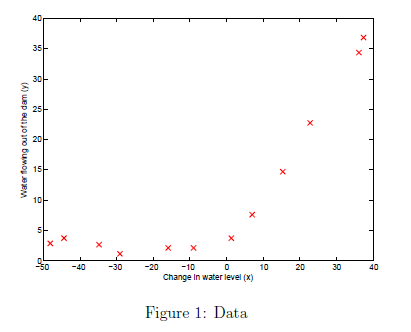

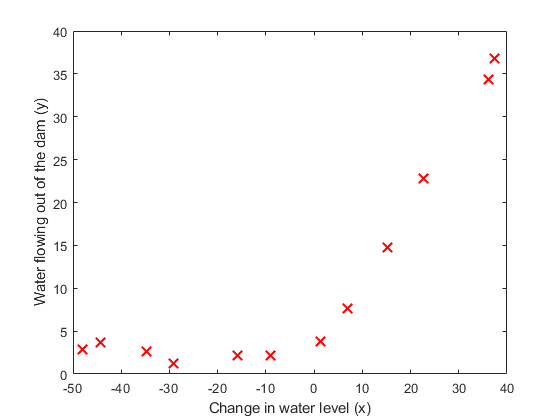

% Load from ex5data1: 
% You will have X, y, Xval, yval, Xtest, ytest in your environment
load ('ex5data1.mat');
% m = Number of examples
m = size(X, 1);

% Plot training data
figure;
plot(X, y, 'rx', 'MarkerSize', 10, 'LineWidth', 1.5);
xlabel('Change in water level (x)');
ylabel('Water flowing out of the dam (y)');

### 1.2 Regularized linear regression cost function

Recall that regularized linear regression has the following cost function:


$$J\left(\theta \right)=\frac{1}{2m}\left(\sum_{i=1}^m {\left(h_{\theta \;} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)}^2 \right)+\frac{\;\lambda }{2m}\left(\sum_{j=1}^n \theta_j^2 \right)$$


where $\lambda$ is a regularization parameter which controls the degree of regularization (thus, helps preventing overfitting). The regularization term puts a penalty on the overall cost $J$. As the magnitudes of the model parameters $\theta_j$ increase, the penalty increases as well. Note that you should not regularize the $\theta_0$ term. (In MATLAB, the $\theta_0$ term is represented as `theta(1)` since indexing in MATLAB starts from 1).

    You should now complete the code in the file `linearRegCostFunction.m`. Your task is to write a function to calculate the regularized linear regression cost function. If possible, try to vectorize your code and avoid writing loops. When you are finished, the code below will run your cost function using `theta` initialized at `[1; 1]`. You should expect to see an output of 303.993.

theta = [1 ; 1];
J = linearRegCostFunction([ones(m, 1) X], y, theta, 1);
fprintf('Cost at theta = [1 ; 1]: %f', J);

Cost at theta = [1 ; 1]: 303.993192

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

### 1.3 Regularized linear regression gradient

Correspondingly, the partial derivative of regularized linear regression's cost for $\theta_j$ is defined as


$$\begin{array}{l}
\frac{\partial J\left(\theta \right)}{\partial \theta_0 }=\frac{\;1}{m}\sum_{i=1}^m \;\left(h_{\theta \;} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)x_j^{\left(i\right)} \;\;\textrm{for}\;\;j=0\\
\frac{\partial J\left(\theta \right)}{\partial \theta_j }=\left(\frac{\;1}{m}\sum_{i=1}^m \;\left(h_{\theta \;} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)x_j^{\left(i\right)} \right)+\frac{\lambda }{m}\theta_j \;\;\;\textrm{for}\;\;j>0
\end{array}$$


In `linearRegCostFunction.m`, add code to calculate the gradient, returning it in the variable `grad`. When you are finished, the code below will run your gradient function using theta initialized at [1; 1]. You should expect to see a gradient of [-15.30; 598.250].

[J, grad] = linearRegCostFunction([ones(m, 1) X], y, theta, 1);
fprintf('Gradient at theta = [1 ; 1]:  [%f; %f] \n',grad(1), grad(2));

Gradient at theta = [1 ; 1]:  [-15.303016; 598.250744] 


*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

### 1.4 Fitting linear regression

Once your cost function and gradient are working correctly, the code in this section will run the code in `trainLinearReg.m` to compute the optimal values of $\theta$. This training function uses `fmincg` to optimize the cost function. In this part, we set regularization parameter $\lambda$ to zero. Because our current implementation of linear regression is trying to fit a 2-dimensional $\theta$, regularization will not be incredibly helpful for a $\theta$ of such low dimension. In the later parts of the exercise, you will be using polynomial regression with regularization.

%  Train linear regression with lambda = 0
lambda = 0;
[theta] = trainLinearReg([ones(m, 1) X], y, lambda);

Iteration     1 | Cost: 1.052435e+02
Iteration     2 | Cost: 2.237391e+01
Iteration     3 | Cost: 2.237391e+01
Iteration     5 | Cost: 2.237391e+01
Iteration     6 | Cost: 2.237391e+01
Iteration     7 | Cost: 2.237391e+01
Iteration     8 | Cost: 2.237391e+01
Iteration     9 | Cost: 2.237391e+01
Iteration    11 | Cost: 2.237391e+01


    Finally, the code below should also plot the best fit line, resulting in an image similar to Figure 2. The best fit line tells us that the model is not a good fit to the data because the data has a nonlinear pattern. 

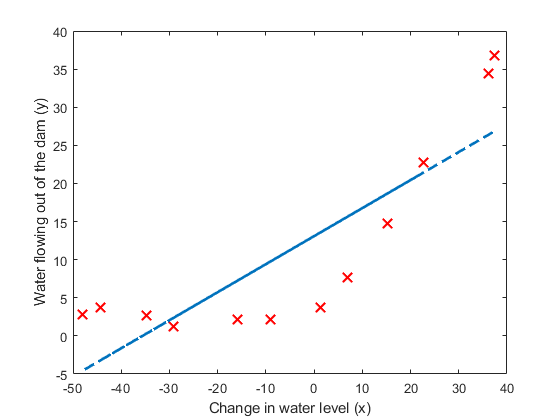

%  Plot fit over the data
figure;
plot(X, y, 'rx', 'MarkerSize', 10, 'LineWidth', 1.5);
xlabel('Change in water level (x)');
ylabel('Water flowing out of the dam (y)');
hold on;
plot(X, [ones(m, 1) X]*theta, '--', 'LineWidth', 2)
hold off;

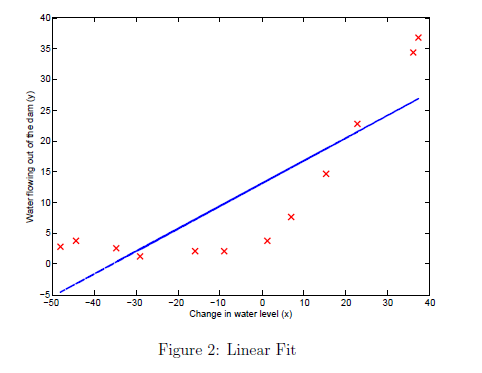

While visualizing the best fit as shown is one possible way to debug your learning algorithm, it is not always easy to visualize the data and model. In the next section, you will implement a function to generate learning curves that can help you debug your learning algorithm even if it is not easy to visualize the data.

## 2. Bias-variance

An important concept in machine learning is the bias-variance tradeoff. Models with high bias are not complex enough for the data and tend to underfit, while models with high variance overfit the training data. In this part of the exercise, you will plot training and test errors on a learning curve to diagnose bias-variance problems.

### 2.1 Learning curves

You will now implement code to generate the learning curves that will be useful in debugging learning algorithms. Recall that a learning curve plots training and cross validation error as a function of training set size. Your job is to fill in `learningCurve.m` so that it returns a vector of errors for the training set and cross validation set.

    To plot the learning curve, we need a training and cross validation set error for different training set sizes. To obtain different training set sizes, you should use different subsets of the original training set `X`. Specically, for a training set size of `i`, you should use the first `i` examples (i.e., `X(1:i,:) `and `y(1:i))`. You can use the `trainLinearReg` function to find the $\theta$ parameters. Note that `lambda` is passed as a parameter to the `learningCurve` function. After learning the $\theta$ parameters, you should compute the error on the training and cross validation sets. Recall that the training error for a dataset is defined as


$$J_{\textrm{train}} \left(\theta \right)=\frac{1}{2m}\left\lbrack \sum_{i=1}^m {\left(h_{\theta \;} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)}^2 \right\rbrack$$


    In particular, note that the training error does not include the regularization term. One way to compute the training error is to use your existing cost function and set $\lambda$ to 0 only when using it to compute the training error and cross validation error. When you are computing the training set error, make sure you compute it on the training subset (i.e., `X(1:n,:)` and `y(1:n)`, instead of the entire training set). However, for the cross validation error, you should compute it over the entire cross validation set. You should store the computed errors in the vectors `error_train` and `error_val`.  

    In Figure 3, you can observe that both the train error and cross validation error are high when the number of training examples is increased. This reflects a high bias problem in the model - the linear regression model is too simple and is unable to fit our dataset well. In the next section, you will implement polynomial regression to fit a better model for this dataset.

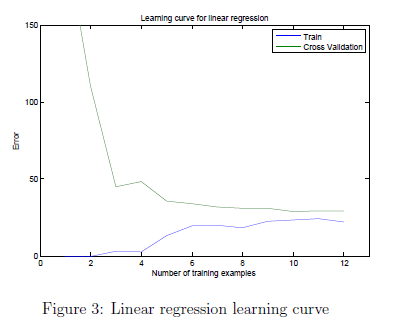

    When you are finished, run the code below to compute the learning curves and produce a plot similar to Figure 3.

lambda = 0;
[error_train, error_val] = learningCurve([ones(m, 1) X], y, [ones(size(Xval, 1), 1) Xval], yval, lambda);

Iteration     1 | Cost: 2.663868e-01
Iteration     2 | Cost: 3.944305e-31
Iteration     3 | Cost: 0.000000e+00


theta =     0.0084
   -0.1334


Iteration     1 | Cost: 4.282328e-01
Iteration     2 | Cost: 8.295365e-30
Iteration     3 | Cost: 4.930381e-32


theta =     3.2932
    0.0727


Iteration     1 | Cost: 1.021540e+02
Iteration     2 | Cost: 3.286595e+00


theta =    14.1550
    0.5391


Iteration     1 | Cost: 1.438726e+02
Iteration     2 | Cost: 1.035224e+02
Iteration     3 | Cost: 7.536716e+01
Iteration     4 | Cost: 1.615422e+01
Iteration     5 | Cost: 3.619255e+00
Iteration     6 | Cost: 2.842916e+00
Iteration     7 | Cost: 2.842916e+00
Iteration     8 | Cost: 2.842770e+00
Iteration     9 | Cost: 2.842731e+00
Iteration    10 | Cost: 2.842729e+00
Iteration    11 | Cost: 2.842678e+00


theta =    14.6243
    0.5599


Iteration     1 | Cost: 1.592641e+02
Iteration     2 | Cost: 2.404966e+01
Iteration     3 | Cost: 2.354137e+01
Iteration     4 | Cost: 2.281160e+01
Iteration     5 | Cost: 2.276969e+01
Iteration     6 | Cost: 2.224060e+01
Iteration     7 | Cost: 1.920606e+01
Iteration     8 | Cost: 1.475292e+01
Iteration     9 | Cost: 1.430565e+01
Iteration    10 | Cost: 1.388881e+01
Iteration    11 | Cost: 1.327330e+01
Iteration    12 | Cost: 1.323519e+01
Iteration    13 | Cost: 1.319411e+01
Iteration    14 | Cost: 1.317355e+01
Iteration    15 | Cost: 1.315411e+01
Iteration    16 | Cost: 1.315405e+01
Iteration    17 | Cost: 1.315405e+01
Iteration    18 | Cost: 1.315405e+01
Iteration    19 | Cost: 1.315405e+01
Iteration    20 | Cost: 1.315405e+01
Iteration    21 | Cost: 1.315405e+01
Iteration    22 | Cost: 1.315405e+01
Iteration    23 | Cost: 1.315405e+01


theta =    17.2138
    0.4497


Iteration     1 | Cost: 1.531141e+02
Iteration     2 | Cost: 1.350947e+02
Iteration     3 | Cost: 1.137334e+02
Iteration     4 | Cost: 4.404199e+01
Iteration     5 | Cost: 2.957435e+01
Iteration     6 | Cost: 2.719561e+01
Iteration     7 | Cost: 1.949283e+01
Iteration     8 | Cost: 1.949128e+01
Iteration     9 | Cost: 1.945708e+01
Iteration    10 | Cost: 1.944472e+01
Iteration    11 | Cost: 1.944472e+01
Iteration    12 | Cost: 1.944471e+01
Iteration    13 | Cost: 1.944453e+01
Iteration    14 | Cost: 1.944425e+01
Iteration    15 | Cost: 1.944411e+01
Iteration    16 | Cost: 1.944396e+01
Iteration    17 | Cost: 1.944396e+01
Iteration    18 | Cost: 1.944396e+01
Iteration    19 | Cost: 1.944396e+01
Iteration    20 | Cost: 1.944396e+01
Iteration    21 | Cost: 1.944396e+01
Iteration    22 | Cost: 1.944396e+01


theta =    15.4049
    0.4574


Iteration     1 | Cost: 1.383936e+02
Iteration     2 | Cost: 1.210275e+02
Iteration     3 | Cost: 1.013004e+02
Iteration     4 | Cost: 3.457729e+01
Iteration     5 | Cost: 2.808710e+01
Iteration     6 | Cost: 2.732288e+01
Iteration     7 | Cost: 2.011513e+01
Iteration     8 | Cost: 2.011508e+01
Iteration     9 | Cost: 2.010693e+01
Iteration    10 | Cost: 2.010640e+01
Iteration    11 | Cost: 2.010629e+01
Iteration    12 | Cost: 2.010382e+01
Iteration    13 | Cost: 2.009852e+01


theta =    14.2668
    0.4368


Iteration     1 | Cost: 1.237772e+02
Iteration     2 | Cost: 1.202532e+02
Iteration     3 | Cost: 1.195134e+02
Iteration     4 | Cost: 9.334231e+01
Iteration     5 | Cost: 4.813526e+01
Iteration     6 | Cost: 2.650400e+01
Iteration     7 | Cost: 1.927314e+01
Iteration     8 | Cost: 1.826693e+01
Iteration     9 | Cost: 1.817331e+01
Iteration    10 | Cost: 1.817289e+01
Iteration    11 | Cost: 1.817288e+01
Iteration    12 | Cost: 1.817286e+01
Iteration    13 | Cost: 1.817286e+01
Iteration    14 | Cost: 1.817286e+01
Iteration    15 | Cost: 1.817286e+01
Iteration    16 | Cost: 1.817286e+01
Iteration    17 | Cost: 1.817286e+01
Iteration    18 | Cost: 1.817286e+01
Iteration    20 | Cost: 1.817286e+01
Iteration    22 | Cost: 1.817286e+01


theta =    14.6234
    0.4231


Iteration     1 | Cost: 1.089984e+02
Iteration     2 | Cost: 1.064701e+02
Iteration     3 | Cost: 1.054742e+02
Iteration     4 | Cost: 2.266786e+01
Iteration     5 | Cost: 2.266786e+01
Iteration     6 | Cost: 2.266758e+01
Iteration     7 | Cost: 2.260941e+01


theta =    13.2966
    0.4130


Iteration     1 | Cost: 1.108611e+02
Iteration     2 | Cost: 2.497543e+01
Iteration     3 | Cost: 2.496421e+01
Iteration     4 | Cost: 2.494838e+01
Iteration     5 | Cost: 2.493176e+01
Iteration     6 | Cost: 2.490654e+01
Iteration     7 | Cost: 2.474429e+01
Iteration     8 | Cost: 2.326181e+01
Iteration     9 | Cost: 2.326181e+01
Iteration    10 | Cost: 2.326176e+01
Iteration    11 | Cost: 2.326175e+01
Iteration    12 | Cost: 2.326169e+01
Iteration    13 | Cost: 2.326147e+01
Iteration    14 | Cost: 2.326147e+01
Iteration    15 | Cost: 2.326147e+01
Iteration    16 | Cost: 2.326146e+01
Iteration    17 | Cost: 2.326146e+01
Iteration    18 | Cost: 2.326146e+01
Iteration    19 | Cost: 2.326146e+01
Iteration    20 | Cost: 2.326146e+01
Iteration    21 | Cost: 2.326146e+01
Iteration    22 | Cost: 2.326146e+01
Iteration    23 | Cost: 2.326146e+01
Iteration    24 | Cost: 2.326146e+01
Iteration    25 | Cost: 2.326146e+01
Iteration    26 | Cost: 2.326146e+01
Iteration    28 | Cost: 2.326146e+01
I

theta =    13.8537
    0.3778


Iteration     1 | Cost: 1.023394e+02
Iteration     2 | Cost: 2.443039e+01
Iteration     3 | Cost: 2.443033e+01
Iteration     4 | Cost: 2.442972e+01
Iteration     5 | Cost: 2.441042e+01
Iteration     6 | Cost: 2.435852e+01
Iteration     7 | Cost: 2.431735e+01
Iteration     8 | Cost: 2.431733e+01
Iteration     9 | Cost: 2.431727e+01
Iteration    10 | Cost: 2.431725e+01
Iteration    11 | Cost: 2.431725e+01


theta =    12.9372
    0.3634


Iteration     1 | Cost: 1.052435e+02
Iteration     2 | Cost: 2.237391e+01
Iteration     3 | Cost: 2.237391e+01
Iteration     5 | Cost: 2.237391e+01
Iteration     6 | Cost: 2.237391e+01
Iteration     7 | Cost: 2.237391e+01
Iteration     8 | Cost: 2.237391e+01
Iteration     9 | Cost: 2.237391e+01
Iteration    11 | Cost: 2.237391e+01


theta =    13.0879
    0.3678


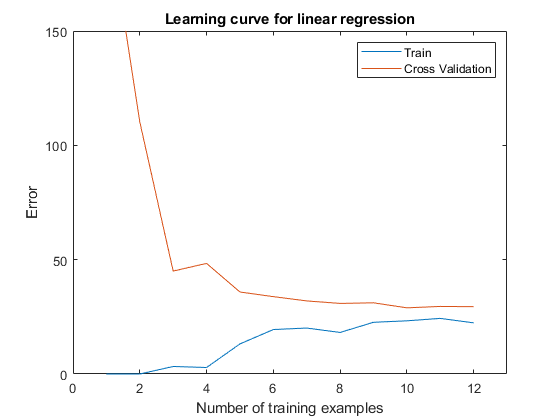


plot(1:m, error_train, 1:m, error_val);
title('Learning curve for linear regression')
legend('Train', 'Cross Validation')
xlabel('Number of training examples')
ylabel('Error')
axis([0 13 0 150])


fprintf('# Training Examples\tTrain Error\tCross Validation Error\n');

# Training Examples	Train Error	Cross Validation Error


for i = 1:m
    fprintf('  \t%d\t\t%f\t%f\n', i, error_train(i), error_val(i));
end

  	1		0.000000	205.121096
  	2		0.000000	110.300366
  	3		3.286595	45.010231
  	4		2.842678	48.368911
  	5		13.154049	35.865165
  	6		19.443963	33.829962
  	7		20.098522	31.970986
  	8		18.172859	30.862446
  	9		22.609405	31.135998
  	10		23.261462	28.936207
  	11		24.317250	29.551432
  	12		22.373906	29.433818


## 3. Polynomial regression

The problem with our linear model was that it was too simple for the data and resulted in underfitting (high bias). In this part of the exercise, you will address this problem by adding more features. For use polynomial regression, our hypothesis has the form:


$$h_\theta(x) =\theta_0+\theta_1\ast (waterLevel)+\theta_2*
(waterLevel)^2+\cdots+\theta_p\ast (waterLevel)^p \\
\qquad\;=\theta_0+\theta_1 x_1+\theta_2 x_2+\cdots+\theta_p x_p \end{aligned}$$


Notice that by defining $x_1 = (\text{waterLevel}), x_2 = (\text{waterLevel)}^2,\ldots,x_p = (\text{waterLevel})^p$, we obtain a linear regression model where the features are the various powers of the original value (*waterLevel*).

    Now, you will add more features using the higher powers of the existing feature $x$ in the dataset. Your task in this part is to complete the code in `polyFeatures.`m so that the function maps the original training set `X` of size $m\times 1$into its higher powers. Specifically, when a training set $X$ of size $m\times 1$ is passed into the function, the function should return a $m\times p$ matrix `X_poly`, where column 1 holds the original values of `X`, column 2 holds the values of `X.^2`, column 3 holds the values of `X.^3`, and so on. Note that you don't have to account for the zero-th power in this function. Now that you have a function that will map features to a higher dimension, the code in the next section will apply it to the training set, the test set, and the cross validation set (which you haven't used yet).

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

### 3.1 Learning Polynomial Regression

After you have completed `polyFeatures.m`, run the code below to train polynomial regression using your linear regression cost function. Keep in mind that even though we have polynomial terms in our feature vector, we are still solving a linear regression optimization problem. The polynomial terms have simply turned into features that we can use for linear regression. We are using the same cost function and gradient that you wrote for the earlier part of this exercise.

    For this part of the exercise, you will be using a polynomial of degree 8. It turns out that if we run the training directly on the projected data, it will not work well as the features would be badly scaled (e.g., an example with $x = 40$ will now have a feature $x_8 = 40^8 = 6:5\times 10^{12$) Therefore, you will need to use feature normalization. Before learning the parameters $\theta$ for the polynomial regression, code in below will first call `featureNormalize` to normalize the features of the training set, storing the `mu`, `sigma` parameters separately. We have already implemented this function for you and it is the same function from the first exercise.

p = 8;

% Map X onto Polynomial Features and Normalize
X_poly = polyFeatures(X, p);
[X_poly, mu, sigma] = featureNormalize(X_poly);  % Normalize
X_poly = [ones(m, 1), X_poly];                   % Add Ones

% Map X_poly_test and normalize (using mu and sigma)
X_poly_test = polyFeatures(Xtest, p);
X_poly_test = X_poly_test-mu; % uses implicit expansion instead of bsxfun
X_poly_test = X_poly_test./sigma; % uses implicit expansion instead of bsxfun
X_poly_test = [ones(size(X_poly_test, 1), 1), X_poly_test];         % Add Ones

% Map X_poly_val and normalize (using mu and sigma)
X_poly_val = polyFeatures(Xval, p);
X_poly_val = X_poly_val-mu; % uses implicit expansion instead of bsxfun
X_poly_val = X_poly_val./sigma; % uses implicit expansion instead of bsxfun
X_poly_val = [ones(size(X_poly_val, 1), 1), X_poly_val];           % Add Ones

fprintf('Normalized Training Example 1:\n');

Normalized Training Example 1:


fprintf('  %f  \n', X_poly(1, :));

  1.000000  
  -0.362141  
  -0.755087  
  0.182226  
  -0.706190  
  0.306618  
  -0.590878  
  0.344516  
  -0.508481  


% Train the model
lambda = 0;
[theta] = trainLinearReg(X_poly, y, lambda);

Iteration     1 | Cost: 8.273077e+01
Iteration     2 | Cost: 2.687496e+01
Iteration     3 | Cost: 1.327780e+01
Iteration     4 | Cost: 3.455324e+00
Iteration     5 | Cost: 2.870493e+00
Iteration     6 | Cost: 2.404364e+00
Iteration     7 | Cost: 2.372779e+00
Iteration     8 | Cost: 1.771555e+00
Iteration     9 | Cost: 1.210317e+00
Iteration    10 | Cost: 9.413710e-01
Iteration    11 | Cost: 7.664150e-01
Iteration    12 | Cost: 6.504421e-01
Iteration    13 | Cost: 5.859279e-01
Iteration    14 | Cost: 5.490372e-01
Iteration    15 | Cost: 5.065777e-01
Iteration    16 | Cost: 4.806162e-01
Iteration    17 | Cost: 4.735173e-01
Iteration    18 | Cost: 4.662764e-01
Iteration    19 | Cost: 4.556416e-01
Iteration    20 | Cost: 4.450352e-01
Iteration    21 | Cost: 4.244435e-01
Iteration    22 | Cost: 4.118416e-01
Iteration    23 | Cost: 3.955800e-01
Iteration    24 | Cost: 3.805369e-01
Iteration    25 | Cost: 3.797197e-01
Iteration    26 | Cost: 3.751002e-01
Iteration    27 | Cost: 3.734674e-01
I

After learning the parameters $\theta$, the code below will generate two plots (Figures 4,5) for polynomial regression with $\lambda = 0$. 

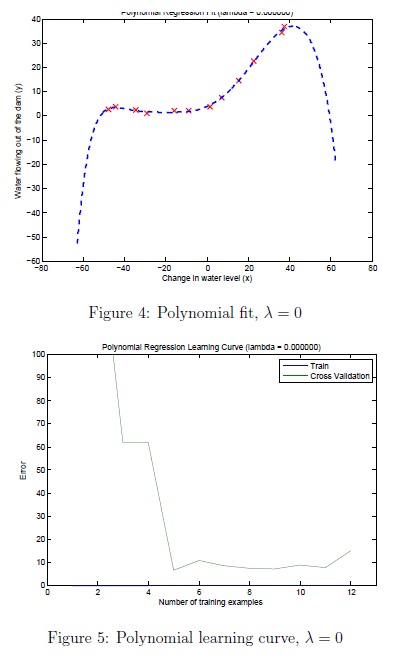

From Figure 4, you should see that the polynomial fit is able to follow the datapoints very well - thus, obtaining a low training error. However, the polynomial fit is very complex and even drops off at the extremes. This is an indicator that the polynomial regression model is overfitting the training data and will not generalize well.

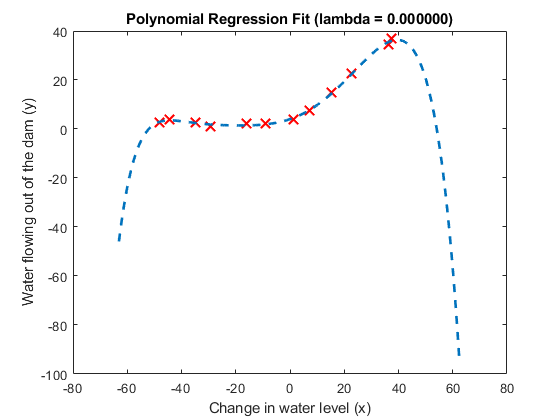

% Plot training data and fit
plot(X, y, 'rx', 'MarkerSize', 10, 'LineWidth', 1.5);
plotFit(min(X), max(X), mu, sigma, theta, p);
xlabel('Change in water level (x)');
ylabel('Water flowing out of the dam (y)');
title (sprintf('Polynomial Regression Fit (lambda = %f)', lambda));

[error_train, error_val] = learningCurve(X_poly, y, X_poly_val, yval, lambda);

Iteration     1 | Cost: 3.386454e-01
Iteration     2 | Cost: 0.000000e+00


theta =     0.6989
   -0.2531
   -0.5278
    0.1274
   -0.4936
    0.2143
   -0.4130
    0.2408
   -0.3554


Iteration     1 | Cost: 5.373343e-02
Iteration     2 | Cost: 2.656989e-04
Iteration     3 | Cost: 1.480972e-05
Iteration     4 | Cost: 1.880576e-10
Iteration     5 | Cost: 1.880553e-10
Iteration     6 | Cost: 9.442954e-11
Iteration     7 | Cost: 6.841388e-15
Iteration     8 | Cost: 6.840914e-15
Iteration     9 | Cost: 3.450009e-15
Iteration    10 | Cost: 1.012558e-18
Iteration    11 | Cost: 1.012253e-18
Iteration    12 | Cost: 4.823455e-19
Iteration    13 | Cost: 4.688636e-21
Iteration    14 | Cost: 2.246403e-21
Iteration    15 | Cost: 1.707239e-23
Iteration    16 | Cost: 8.176013e-24
Iteration    17 | Cost: 6.342162e-26
Iteration    18 | Cost: 3.030749e-26
Iteration    19 | Cost: 2.544693e-28
Iteration    20 | Cost: 1.136453e-28
Iteration    21 | Cost: 6.569732e-30
Iteration    22 | Cost: 3.907327e-30
Iteration    23 | Cost: 2.095412e-31
Iteration    24 | Cost: 1.232595e-32
Iteration    26 | Cost: 0.000000e+00


theta =     0.5958
   -0.0733
   -0.6941
    0.2475
   -0.5432
    0.2515
   -0.4021
    0.2340
   -0.3222


Iteration     1 | Cost: 3.023381e+01
Iteration     2 | Cost: 9.745401e-01
Iteration     3 | Cost: 4.827305e-01
Iteration     4 | Cost: 1.170249e-02
Iteration     5 | Cost: 9.696908e-04
Iteration     6 | Cost: 5.299258e-04
Iteration     7 | Cost: 1.985836e-04
Iteration     8 | Cost: 6.032119e-05
Iteration     9 | Cost: 6.225212e-07
Iteration    10 | Cost: 3.894758e-07
Iteration    11 | Cost: 7.703724e-08
Iteration    12 | Cost: 5.688321e-08
Iteration    13 | Cost: 5.385450e-09
Iteration    14 | Cost: 1.603656e-10
Iteration    15 | Cost: 1.516867e-11
Iteration    16 | Cost: 9.627464e-12
Iteration    17 | Cost: 2.794098e-12
Iteration    18 | Cost: 7.766256e-13
Iteration    19 | Cost: 1.571268e-13
Iteration    20 | Cost: 2.248292e-16
Iteration    21 | Cost: 5.079311e-17
Iteration    22 | Cost: 1.499570e-17
Iteration    23 | Cost: 3.850967e-18
Iteration    24 | Cost: 3.286920e-32


theta =     6.3942
    6.0725
    6.1249
    5.6590
    2.6152
    5.0238
    0.2492
    4.2528
   -1.0254


Iteration     1 | Cost: 7.960488e-01
Iteration     2 | Cost: 2.114171e-01
Iteration     3 | Cost: 2.702642e-02
Iteration     4 | Cost: 3.974598e-19
Iteration     5 | Cost: 3.036925e-25
Iteration     6 | Cost: 1.125166e-25
Iteration     7 | Cost: 7.946048e-28


theta =     6.5574
    7.5559
    6.9020
    5.1406
    1.9603
    3.8532
   -0.9940
    3.0128
   -2.2925


Iteration     1 | Cost: 9.143237e+01
Iteration     2 | Cost: 2.716415e+01
Iteration     3 | Cost: 2.300956e+00
Iteration     4 | Cost: 1.375885e+00
Iteration     5 | Cost: 4.516285e-01
Iteration     6 | Cost: 1.662103e-01
Iteration     7 | Cost: 8.832511e-02
Iteration     8 | Cost: 8.053439e-02
Iteration     9 | Cost: 7.272179e-02
Iteration    10 | Cost: 6.568472e-02
Iteration    11 | Cost: 6.150690e-02
Iteration    12 | Cost: 5.582162e-02
Iteration    13 | Cost: 5.071904e-02
Iteration    14 | Cost: 4.622942e-02
Iteration    15 | Cost: 4.126764e-02
Iteration    16 | Cost: 3.744913e-02
Iteration    17 | Cost: 3.532611e-02
Iteration    18 | Cost: 3.370456e-02
Iteration    19 | Cost: 3.321504e-02
Iteration    20 | Cost: 3.274240e-02
Iteration    21 | Cost: 3.250231e-02
Iteration    22 | Cost: 2.673794e-02
Iteration    23 | Cost: 2.518710e-02
Iteration    24 | Cost: 2.483744e-02
Iteration    25 | Cost: 2.447843e-02
Iteration    26 | Cost: 2.199770e-02
Iteration    27 | Cost: 1.921882e-02
I

theta =    10.4185
    8.3484
    5.5788
    5.1725
    2.6396
    2.0799
    1.0140
    0.1542
    0.4297


Iteration     1 | Cost: 6.685771e+01
Iteration     2 | Cost: 1.216701e+01
Iteration     3 | Cost: 1.795979e+00
Iteration     4 | Cost: 6.292963e-01
Iteration     5 | Cost: 2.225698e-01
Iteration     6 | Cost: 5.075312e-02
Iteration     7 | Cost: 4.971823e-02
Iteration     8 | Cost: 4.887206e-02
Iteration     9 | Cost: 4.848309e-02
Iteration    10 | Cost: 4.805707e-02
Iteration    11 | Cost: 4.762090e-02
Iteration    12 | Cost: 4.708634e-02
Iteration    13 | Cost: 4.655854e-02
Iteration    14 | Cost: 4.629423e-02
Iteration    15 | Cost: 4.627931e-02
Iteration    16 | Cost: 4.609345e-02
Iteration    17 | Cost: 4.591964e-02
Iteration    18 | Cost: 4.578070e-02
Iteration    19 | Cost: 4.548264e-02
Iteration    20 | Cost: 4.418428e-02
Iteration    21 | Cost: 4.299050e-02
Iteration    22 | Cost: 3.714620e-02
Iteration    23 | Cost: 3.655730e-02
Iteration    24 | Cost: 3.230304e-02
Iteration    25 | Cost: 3.182865e-02
Iteration    26 | Cost: 2.564036e-02
Iteration    27 | Cost: 2.518747e-02
I

theta =     9.2973
    5.0484
    9.0614
   11.0282
   -1.9255
    2.9129
    0.2691
   -3.8649
    2.5327


Iteration     1 | Cost: 7.107198e+01
Iteration     2 | Cost: 4.525377e+00
Iteration     3 | Cost: 3.204182e+00
Iteration     4 | Cost: 1.702807e+00
Iteration     5 | Cost: 1.447094e+00
Iteration     6 | Cost: 1.188390e+00
Iteration     7 | Cost: 1.085252e+00
Iteration     8 | Cost: 9.660387e-01
Iteration     9 | Cost: 8.267521e-01
Iteration    10 | Cost: 8.052883e-01
Iteration    11 | Cost: 7.141038e-01
Iteration    12 | Cost: 6.567789e-01
Iteration    13 | Cost: 6.073580e-01
Iteration    14 | Cost: 5.252386e-01
Iteration    15 | Cost: 5.066478e-01
Iteration    16 | Cost: 4.931504e-01
Iteration    17 | Cost: 4.820232e-01
Iteration    18 | Cost: 4.588473e-01
Iteration    19 | Cost: 4.369162e-01
Iteration    20 | Cost: 4.196205e-01
Iteration    21 | Cost: 4.069902e-01
Iteration    22 | Cost: 3.418050e-01
Iteration    23 | Cost: 3.033648e-01
Iteration    24 | Cost: 2.750688e-01
Iteration    25 | Cost: 2.314939e-01
Iteration    26 | Cost: 1.969652e-01
Iteration    27 | Cost: 1.753869e-01
I

theta =    10.5816
   12.7997
   13.3437
   -2.9230
  -15.8570
    5.0656
    2.0231
    4.2446
   12.6670


Iteration     1 | Cost: 6.233475e+01
Iteration     2 | Cost: 3.419151e+00
Iteration     3 | Cost: 2.267331e+00
Iteration     4 | Cost: 1.662505e+00
Iteration     5 | Cost: 1.311645e+00
Iteration     6 | Cost: 1.236407e+00
Iteration     7 | Cost: 1.142743e+00
Iteration     8 | Cost: 9.336246e-01
Iteration     9 | Cost: 8.854225e-01
Iteration    10 | Cost: 6.911793e-01
Iteration    11 | Cost: 6.693097e-01
Iteration    12 | Cost: 4.324014e-01
Iteration    13 | Cost: 3.079844e-01
Iteration    14 | Cost: 2.580379e-01
Iteration    15 | Cost: 2.405774e-01
Iteration    16 | Cost: 1.181395e-01
Iteration    17 | Cost: 1.058102e-01
Iteration    18 | Cost: 1.038786e-01
Iteration    19 | Cost: 1.020275e-01
Iteration    20 | Cost: 9.751887e-02
Iteration    21 | Cost: 9.713952e-02
Iteration    22 | Cost: 9.617586e-02
Iteration    23 | Cost: 9.555557e-02
Iteration    24 | Cost: 9.455117e-02
Iteration    25 | Cost: 9.251219e-02
Iteration    26 | Cost: 9.199115e-02
Iteration    27 | Cost: 9.195239e-02
I

theta =    11.3038
   13.2463
    8.2530
   -2.8789
   -4.0954
    0.2669
    4.1244
    6.4120
    2.0947


Iteration     1 | Cost: 5.922449e+01
Iteration     2 | Cost: 2.724806e+00
Iteration     3 | Cost: 1.507147e+00
Iteration     4 | Cost: 1.432124e+00
Iteration     5 | Cost: 1.346576e+00
Iteration     6 | Cost: 1.176237e+00
Iteration     7 | Cost: 1.075486e+00
Iteration     8 | Cost: 7.346302e-01
Iteration     9 | Cost: 6.701848e-01
Iteration    10 | Cost: 4.832152e-01
Iteration    11 | Cost: 4.385125e-01
Iteration    12 | Cost: 4.159817e-01
Iteration    13 | Cost: 4.062100e-01
Iteration    14 | Cost: 3.955466e-01
Iteration    15 | Cost: 3.691595e-01
Iteration    16 | Cost: 3.651812e-01
Iteration    17 | Cost: 3.481128e-01
Iteration    18 | Cost: 3.466678e-01
Iteration    19 | Cost: 3.423189e-01
Iteration    20 | Cost: 3.380370e-01
Iteration    21 | Cost: 3.370712e-01
Iteration    22 | Cost: 3.358274e-01
Iteration    23 | Cost: 3.336722e-01
Iteration    24 | Cost: 3.323856e-01
Iteration    25 | Cost: 3.313370e-01
Iteration    26 | Cost: 3.283980e-01
Iteration    27 | Cost: 3.246508e-01
I

theta =    10.9716
   11.9665
   14.5452
    4.1694
  -14.4432
   -7.2448
    6.1092
    6.4885
    2.8898


Iteration     1 | Cost: 5.599132e+01
Iteration     2 | Cost: 2.031443e+00
Iteration     3 | Cost: 1.571698e+00
Iteration     4 | Cost: 1.447171e+00
Iteration     5 | Cost: 1.313347e+00
Iteration     6 | Cost: 1.243444e+00
Iteration     7 | Cost: 1.197066e+00
Iteration     8 | Cost: 9.082508e-01
Iteration     9 | Cost: 7.443976e-01
Iteration    10 | Cost: 6.495926e-01
Iteration    11 | Cost: 5.231557e-01
Iteration    12 | Cost: 4.325733e-01
Iteration    13 | Cost: 4.022622e-01
Iteration    14 | Cost: 3.741455e-01
Iteration    15 | Cost: 3.691473e-01
Iteration    16 | Cost: 3.637843e-01
Iteration    17 | Cost: 3.624178e-01
Iteration    18 | Cost: 3.513032e-01
Iteration    19 | Cost: 3.497309e-01
Iteration    20 | Cost: 3.436771e-01
Iteration    21 | Cost: 3.408081e-01
Iteration    22 | Cost: 3.336048e-01
Iteration    23 | Cost: 3.319470e-01
Iteration    24 | Cost: 3.297093e-01
Iteration    25 | Cost: 3.295718e-01
Iteration    26 | Cost: 3.274489e-01
Iteration    27 | Cost: 3.254476e-01
I

theta =    11.1299
   11.4830
   15.6931
    8.9575
  -19.1038
  -15.8608
   15.4164
    9.7865
   -3.7783


Iteration     1 | Cost: 7.186879e+01
Iteration     2 | Cost: 2.278130e+01
Iteration     3 | Cost: 4.970159e+00
Iteration     4 | Cost: 1.355413e+00
Iteration     5 | Cost: 1.252814e+00
Iteration     6 | Cost: 1.187922e+00
Iteration     7 | Cost: 1.158229e+00
Iteration     8 | Cost: 1.038217e+00
Iteration     9 | Cost: 9.139054e-01
Iteration    10 | Cost: 8.983327e-01
Iteration    11 | Cost: 8.343376e-01
Iteration    12 | Cost: 7.911677e-01
Iteration    13 | Cost: 6.716096e-01
Iteration    14 | Cost: 4.938530e-01
Iteration    15 | Cost: 4.864812e-01
Iteration    16 | Cost: 4.680356e-01
Iteration    17 | Cost: 3.983360e-01
Iteration    18 | Cost: 3.853041e-01
Iteration    19 | Cost: 3.683818e-01
Iteration    20 | Cost: 3.666197e-01
Iteration    21 | Cost: 3.603017e-01
Iteration    22 | Cost: 3.570466e-01
Iteration    23 | Cost: 3.435379e-01
Iteration    24 | Cost: 3.391643e-01
Iteration    25 | Cost: 3.221206e-01
Iteration    26 | Cost: 3.154008e-01
Iteration    27 | Cost: 3.086188e-01
I

theta =    11.1296
   11.0573
   14.8789
   10.9665
  -16.7783
  -17.0055
   14.9498
    8.2096
   -6.0529


Iteration     1 | Cost: 8.273077e+01
Iteration     2 | Cost: 2.687496e+01
Iteration     3 | Cost: 1.327780e+01
Iteration     4 | Cost: 3.455324e+00
Iteration     5 | Cost: 2.870493e+00
Iteration     6 | Cost: 2.404364e+00
Iteration     7 | Cost: 2.372779e+00
Iteration     8 | Cost: 1.771555e+00
Iteration     9 | Cost: 1.210317e+00
Iteration    10 | Cost: 9.413710e-01
Iteration    11 | Cost: 7.664150e-01
Iteration    12 | Cost: 6.504421e-01
Iteration    13 | Cost: 5.859279e-01
Iteration    14 | Cost: 5.490372e-01
Iteration    15 | Cost: 5.065777e-01
Iteration    16 | Cost: 4.806162e-01
Iteration    17 | Cost: 4.735173e-01
Iteration    18 | Cost: 4.662764e-01
Iteration    19 | Cost: 4.556416e-01
Iteration    20 | Cost: 4.450352e-01
Iteration    21 | Cost: 4.244435e-01
Iteration    22 | Cost: 4.118416e-01
Iteration    23 | Cost: 3.955800e-01
Iteration    24 | Cost: 3.805369e-01
Iteration    25 | Cost: 3.797197e-01
Iteration    26 | Cost: 3.751002e-01
Iteration    27 | Cost: 3.734674e-01
I

theta =    11.2210
   11.3376
   14.2653
   10.9745
  -10.1949
  -13.1182
    5.2428
    1.4204
   -5.0168


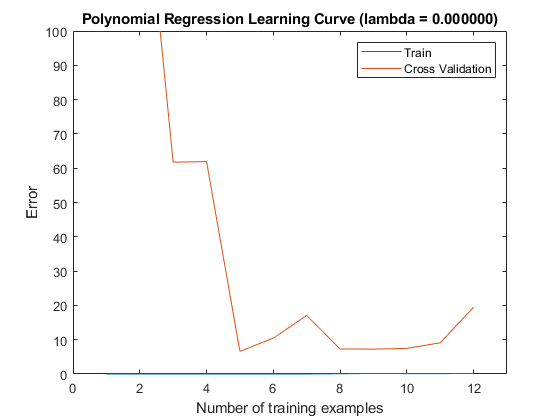

plot(1:m, error_train, 1:m, error_val);
title(sprintf('Polynomial Regression Learning Curve (lambda = %f)', lambda));
xlabel('Number of training examples')
ylabel('Error')
axis([0 13 0 100])
legend('Train', 'Cross Validation')

    To better understand the problems with the unregularized $\lambda=0$ model, you can see that the learning curve (Figure 5) shows the same effect where the low training error is low, but the cross validation error is high. There is a gap between the training and cross validation errors, indicating a high variance problem. One way to combat the overfitting (high-variance) problem is to add regularization to the model. In the next section, you will get to try different $\lambda$ parameters to see how regularization can lead to a better model.

### 3.2 Optional (ungraded) exercise: Adjusting the regularization parameter

In this section, you will get to observe how the regularization parameter affects the bias-variance of regularized polynomial regression. You should now modify the the `lambda` parameter in the code below and try $\lambda = 1,\; 100$. 

% Choose the value of lambda
lambda = 1;
[theta] = trainLinearReg(X_poly, y, lambda);

Iteration     1 | Cost: 8.320954e+01
Iteration     2 | Cost: 2.907694e+01
Iteration     3 | Cost: 1.613078e+01
Iteration     4 | Cost: 8.099229e+00
Iteration     5 | Cost: 7.978585e+00
Iteration     6 | Cost: 7.689198e+00
Iteration     7 | Cost: 7.612530e+00
Iteration     8 | Cost: 7.396000e+00
Iteration     9 | Cost: 7.350173e+00
Iteration    10 | Cost: 7.291198e+00
Iteration    11 | Cost: 7.287920e+00
Iteration    12 | Cost: 7.281753e+00
Iteration    13 | Cost: 7.275793e+00
Iteration    14 | Cost: 7.274328e+00
Iteration    15 | Cost: 7.270014e+00
Iteration    16 | Cost: 7.269538e+00
Iteration    17 | Cost: 7.269020e+00
Iteration    18 | Cost: 7.268392e+00
Iteration    19 | Cost: 7.268362e+00
Iteration    20 | Cost: 7.268325e+00
Iteration    21 | Cost: 7.268219e+00
Iteration    22 | Cost: 7.268170e+00
Iteration    23 | Cost: 7.268168e+00
Iteration    24 | Cost: 7.268158e+00
Iteration    25 | Cost: 7.268157e+00
Iteration    26 | Cost: 7.268153e+00
Iteration    27 | Cost: 7.268151e+00
I

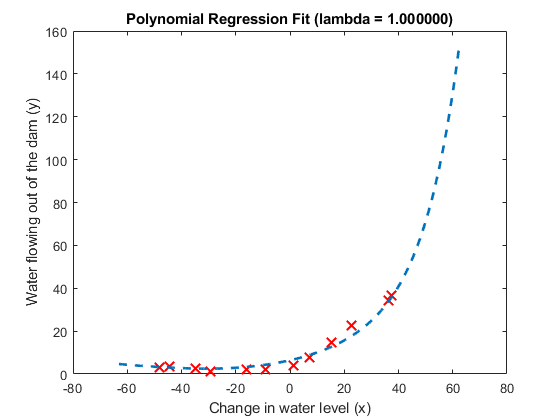


% Plot training data and fit
plot(X, y, 'rx', 'MarkerSize', 10, 'LineWidth', 1.5);
plotFit(min(X), max(X), mu, sigma, theta, p);
xlabel('Change in water level (x)');
ylabel('Water flowing out of the dam (y)');
title (sprintf('Polynomial Regression Fit (lambda = %f)', lambda));

[error_train, error_val] = learningCurve(X_poly, y, X_poly_val, yval, lambda);

Iteration     1 | Cost: 5.280051e-01
Iteration     2 | Cost: 2.083531e-01
Iteration     3 | Cost: 9.810873e-02
Iteration     4 | Cost: 1.501116e-03
Iteration     5 | Cost: 1.089480e-03
Iteration     6 | Cost: 3.537746e-31
Iteration     7 | Cost: 1.070169e-31
Iteration     8 | Cost: 1.165771e-33
Iteration     9 | Cost: 9.868680e-36
Iteration    10 | Cost: 1.213728e-59
Iteration    11 | Cost: 9.159015e-62
Iteration    12 | Cost: 6.911560e-64
Iteration    13 | Cost: 5.215590e-66
Iteration    14 | Cost: 3.935779e-68
Iteration    15 | Cost: 2.970011e-70
Iteration    16 | Cost: 2.241224e-72
Iteration    17 | Cost: 1.691269e-74
Iteration    18 | Cost: 1.276262e-76
Iteration    19 | Cost: 9.630910e-79
Iteration    20 | Cost: 7.267660e-81
Iteration    21 | Cost: 5.484309e-83
Iteration    22 | Cost: 4.138560e-85
Iteration    23 | Cost: 3.123033e-87
Iteration    24 | Cost: 2.356698e-89
Iteration    25 | Cost: 1.778407e-91
Iteration    26 | Cost: 1.342019e-93
Iteration    27 | Cost: 1.012712e-95
I

theta =     2.1343
   -0.0000
   -0.0000
   -0.0000
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000


Iteration     1 | Cost: 2.032751e-01
Iteration     2 | Cost: 1.041953e-01
Iteration     3 | Cost: 7.367762e-02
Iteration     4 | Cost: 7.279642e-02
Iteration     5 | Cost: 7.269797e-02
Iteration     6 | Cost: 7.269533e-02
Iteration     7 | Cost: 7.269502e-02
Iteration     8 | Cost: 7.269437e-02
Iteration     9 | Cost: 7.269436e-02
Iteration    10 | Cost: 7.269436e-02
Iteration    11 | Cost: 7.269436e-02
Iteration    12 | Cost: 7.269436e-02
Iteration    13 | Cost: 7.269436e-02
Iteration    14 | Cost: 7.269436e-02
Iteration    15 | Cost: 7.269436e-02
Iteration    16 | Cost: 7.269436e-02
Iteration    17 | Cost: 7.269436e-02
Iteration    18 | Cost: 7.269436e-02
Iteration    19 | Cost: 7.269436e-02
Iteration    20 | Cost: 7.269436e-02
Iteration    21 | Cost: 7.269436e-02
Iteration    23 | Cost: 7.269436e-02
Iteration    25 | Cost: 7.269436e-02
Iteration    27 | Cost: 7.269436e-02


theta =     1.5366
    0.1334
   -0.2288
    0.1302
   -0.1147
    0.0645
   -0.0469
    0.0270
   -0.0180


Iteration     1 | Cost: 3.958682e+01
Iteration     2 | Cost: 2.172738e+01
Iteration     3 | Cost: 2.007128e+01
Iteration     4 | Cost: 1.908475e+01
Iteration     5 | Cost: 1.903782e+01
Iteration     6 | Cost: 1.872107e+01
Iteration     7 | Cost: 1.855211e+01
Iteration     8 | Cost: 1.852112e+01
Iteration     9 | Cost: 1.850029e+01
Iteration    10 | Cost: 1.849891e+01
Iteration    11 | Cost: 1.849887e+01
Iteration    12 | Cost: 1.849879e+01
Iteration    13 | Cost: 1.849879e+01
Iteration    14 | Cost: 1.849879e+01
Iteration    15 | Cost: 1.849879e+01
Iteration    16 | Cost: 1.849879e+01
Iteration    17 | Cost: 1.849879e+01
Iteration    18 | Cost: 1.849879e+01
Iteration    19 | Cost: 1.849879e+01
Iteration    20 | Cost: 1.849879e+01
Iteration    21 | Cost: 1.849879e+01
Iteration    22 | Cost: 1.849879e+01
Iteration    23 | Cost: 1.849879e+01
Iteration    24 | Cost: 1.849879e+01
Iteration    26 | Cost: 1.849879e+01


theta =    10.4295
    6.5586
    3.4554
    4.2571
    2.6837
    2.5951
    1.7423
    1.5311
    1.0632


Iteration     1 | Cost: 1.883439e+01
Iteration     2 | Cost: 1.695119e+01
Iteration     3 | Cost: 1.546680e+01
Iteration     4 | Cost: 1.486258e+01
Iteration     5 | Cost: 1.462699e+01
Iteration     6 | Cost: 1.460173e+01
Iteration     7 | Cost: 1.458789e+01
Iteration     8 | Cost: 1.458161e+01
Iteration     9 | Cost: 1.457865e+01
Iteration    10 | Cost: 1.457611e+01
Iteration    11 | Cost: 1.457599e+01
Iteration    12 | Cost: 1.457592e+01
Iteration    13 | Cost: 1.457591e+01
Iteration    14 | Cost: 1.457588e+01
Iteration    15 | Cost: 1.457587e+01
Iteration    16 | Cost: 1.457586e+01
Iteration    17 | Cost: 1.457586e+01
Iteration    18 | Cost: 1.457586e+01
Iteration    19 | Cost: 1.457586e+01
Iteration    20 | Cost: 1.457586e+01
Iteration    21 | Cost: 1.457586e+01
Iteration    22 | Cost: 1.457586e+01
Iteration    23 | Cost: 1.457586e+01
Iteration    24 | Cost: 1.457586e+01
Iteration    25 | Cost: 1.457586e+01
Iteration    26 | Cost: 1.457586e+01
Iteration    27 | Cost: 1.457586e+01
I

theta =    10.8907
    6.7348
    3.6769
    4.5100
    2.9536
    2.8468
    1.9864
    1.7437
    1.2568


Iteration     1 | Cost: 9.507932e+01
Iteration     2 | Cost: 3.745281e+01
Iteration     3 | Cost: 1.603853e+01
Iteration     4 | Cost: 1.259101e+01
Iteration     5 | Cost: 1.224802e+01
Iteration     6 | Cost: 1.203685e+01
Iteration     7 | Cost: 1.176671e+01
Iteration     8 | Cost: 1.170499e+01
Iteration     9 | Cost: 1.167549e+01
Iteration    10 | Cost: 1.166583e+01
Iteration    11 | Cost: 1.166400e+01
Iteration    12 | Cost: 1.166153e+01
Iteration    13 | Cost: 1.166135e+01
Iteration    14 | Cost: 1.166109e+01
Iteration    15 | Cost: 1.166098e+01
Iteration    16 | Cost: 1.166097e+01
Iteration    17 | Cost: 1.166085e+01
Iteration    18 | Cost: 1.166083e+01
Iteration    19 | Cost: 1.166082e+01
Iteration    20 | Cost: 1.166075e+01
Iteration    21 | Cost: 1.166074e+01
Iteration    22 | Cost: 1.166073e+01
Iteration    23 | Cost: 1.166072e+01
Iteration    24 | Cost: 1.166072e+01
Iteration    25 | Cost: 1.166072e+01
Iteration    26 | Cost: 1.166072e+01
Iteration    27 | Cost: 1.166072e+01
I

theta =    10.8770
    6.7354
    3.6750
    4.5132
    2.9487
    2.8522
    1.9799
    1.7503
    1.2496


Iteration     1 | Cost: 7.115385e+01
Iteration     2 | Cost: 2.111452e+01
Iteration     3 | Cost: 1.314175e+01
Iteration     4 | Cost: 1.054644e+01
Iteration     5 | Cost: 1.036773e+01
Iteration     6 | Cost: 1.034120e+01
Iteration     7 | Cost: 1.026977e+01
Iteration     8 | Cost: 1.022714e+01
Iteration     9 | Cost: 1.019759e+01
Iteration    10 | Cost: 1.015385e+01
Iteration    11 | Cost: 1.014049e+01
Iteration    12 | Cost: 1.013163e+01
Iteration    13 | Cost: 1.013124e+01
Iteration    14 | Cost: 1.012855e+01
Iteration    15 | Cost: 1.012593e+01
Iteration    16 | Cost: 1.011958e+01
Iteration    17 | Cost: 1.011929e+01
Iteration    18 | Cost: 1.011892e+01
Iteration    19 | Cost: 1.011888e+01
Iteration    20 | Cost: 1.011885e+01
Iteration    21 | Cost: 1.011883e+01
Iteration    22 | Cost: 1.011882e+01
Iteration    23 | Cost: 1.011882e+01
Iteration    24 | Cost: 1.011882e+01
Iteration    25 | Cost: 1.011882e+01
Iteration    26 | Cost: 1.011882e+01
Iteration    27 | Cost: 1.011882e+01
I

theta =    10.1905
    6.5116
    4.4218
    4.5250
    3.1365
    3.0210
    1.9522
    1.9624
    1.1301


Iteration     1 | Cost: 7.518060e+01
Iteration     2 | Cost: 1.412837e+01
Iteration     3 | Cost: 1.231416e+01
Iteration     4 | Cost: 1.002691e+01
Iteration     5 | Cost: 9.839787e+00
Iteration     6 | Cost: 9.646795e+00
Iteration     7 | Cost: 9.516514e+00
Iteration     8 | Cost: 9.502732e+00
Iteration     9 | Cost: 9.433765e+00
Iteration    10 | Cost: 9.430486e+00
Iteration    11 | Cost: 9.425947e+00
Iteration    12 | Cost: 9.421615e+00
Iteration    13 | Cost: 9.420251e+00
Iteration    14 | Cost: 9.418743e+00
Iteration    15 | Cost: 9.418059e+00
Iteration    16 | Cost: 9.417762e+00
Iteration    17 | Cost: 9.416649e+00
Iteration    18 | Cost: 9.416521e+00
Iteration    19 | Cost: 9.416471e+00
Iteration    20 | Cost: 9.416419e+00
Iteration    21 | Cost: 9.416348e+00
Iteration    22 | Cost: 9.416335e+00
Iteration    23 | Cost: 9.416327e+00
Iteration    24 | Cost: 9.416325e+00
Iteration    25 | Cost: 9.416322e+00
Iteration    26 | Cost: 9.416322e+00
Iteration    27 | Cost: 9.416320e+00
I

theta =    10.9237
    7.6554
    3.8984
    4.0432
    2.7162
    2.4767
    1.7531
    1.5295
    1.0868


Iteration     1 | Cost: 6.611004e+01
Iteration     2 | Cost: 1.177052e+01
Iteration     3 | Cost: 8.871741e+00
Iteration     4 | Cost: 8.709040e+00
Iteration     5 | Cost: 8.632347e+00
Iteration     6 | Cost: 8.525026e+00
Iteration     7 | Cost: 8.438127e+00
Iteration     8 | Cost: 8.395443e+00
Iteration     9 | Cost: 8.306328e+00
Iteration    10 | Cost: 8.284391e+00
Iteration    11 | Cost: 8.274826e+00
Iteration    12 | Cost: 8.261382e+00
Iteration    13 | Cost: 8.260882e+00
Iteration    14 | Cost: 8.258711e+00
Iteration    15 | Cost: 8.258012e+00
Iteration    16 | Cost: 8.257374e+00
Iteration    17 | Cost: 8.256547e+00
Iteration    18 | Cost: 8.256271e+00
Iteration    19 | Cost: 8.256255e+00
Iteration    20 | Cost: 8.256234e+00
Iteration    21 | Cost: 8.256230e+00
Iteration    22 | Cost: 8.256229e+00
Iteration    23 | Cost: 8.256224e+00
Iteration    24 | Cost: 8.256224e+00
Iteration    25 | Cost: 8.256224e+00
Iteration    26 | Cost: 8.256224e+00
Iteration    27 | Cost: 8.256224e+00
I

theta =    10.9980
    7.5756
    4.0258
    3.9578
    2.7508
    2.4717
    1.7000
    1.5989
    0.9739


Iteration     1 | Cost: 6.224886e+01
Iteration     2 | Cost: 1.240488e+01
Iteration     3 | Cost: 1.166276e+01
Iteration     4 | Cost: 8.685893e+00
Iteration     5 | Cost: 8.415184e+00
Iteration     6 | Cost: 8.043017e+00
Iteration     7 | Cost: 7.988196e+00
Iteration     8 | Cost: 7.918616e+00
Iteration     9 | Cost: 7.875987e+00
Iteration    10 | Cost: 7.862113e+00
Iteration    11 | Cost: 7.841694e+00
Iteration    12 | Cost: 7.831464e+00
Iteration    13 | Cost: 7.823908e+00
Iteration    14 | Cost: 7.819628e+00
Iteration    15 | Cost: 7.814610e+00
Iteration    16 | Cost: 7.808563e+00
Iteration    17 | Cost: 7.805855e+00
Iteration    18 | Cost: 7.805786e+00
Iteration    19 | Cost: 7.803433e+00
Iteration    20 | Cost: 7.803223e+00
Iteration    21 | Cost: 7.802934e+00
Iteration    22 | Cost: 7.802628e+00
Iteration    23 | Cost: 7.802347e+00
Iteration    24 | Cost: 7.802216e+00
Iteration    25 | Cost: 7.802140e+00
Iteration    26 | Cost: 7.802093e+00
Iteration    27 | Cost: 7.802078e+00
I

theta =    10.5912
    7.3473
    4.6339
    4.0385
    2.7751
    2.5740
    1.6379
    1.7033
    0.8915


Iteration     1 | Cost: 5.861091e+01
Iteration     2 | Cost: 1.029928e+01
Iteration     3 | Cost: 1.000150e+01
Iteration     4 | Cost: 8.267232e+00
Iteration     5 | Cost: 7.746579e+00
Iteration     6 | Cost: 7.274815e+00
Iteration     7 | Cost: 7.194562e+00
Iteration     8 | Cost: 7.152572e+00
Iteration     9 | Cost: 7.097860e+00
Iteration    10 | Cost: 7.093539e+00
Iteration    11 | Cost: 7.087825e+00
Iteration    12 | Cost: 7.072839e+00
Iteration    13 | Cost: 7.069088e+00
Iteration    14 | Cost: 7.066117e+00
Iteration    15 | Cost: 7.065074e+00
Iteration    16 | Cost: 7.064713e+00
Iteration    17 | Cost: 7.064497e+00
Iteration    18 | Cost: 7.064468e+00
Iteration    19 | Cost: 7.064433e+00
Iteration    20 | Cost: 7.064418e+00
Iteration    21 | Cost: 7.064415e+00
Iteration    22 | Cost: 7.064404e+00
Iteration    23 | Cost: 7.064403e+00
Iteration    24 | Cost: 7.064402e+00
Iteration    25 | Cost: 7.064399e+00
Iteration    26 | Cost: 7.064398e+00
Iteration    27 | Cost: 7.064398e+00
I

theta =    10.6842
    7.3447
    4.7111
    3.9310
    2.8775
    2.4998
    1.6461
    1.7476
    0.7563


Iteration     1 | Cost: 7.248552e+01
Iteration     2 | Cost: 2.583449e+01
Iteration     3 | Cost: 8.711534e+00
Iteration     4 | Cost: 6.790164e+00
Iteration     5 | Cost: 6.687293e+00
Iteration     6 | Cost: 6.663962e+00
Iteration     7 | Cost: 6.595243e+00
Iteration     8 | Cost: 6.538932e+00
Iteration     9 | Cost: 6.513460e+00
Iteration    10 | Cost: 6.477429e+00
Iteration    11 | Cost: 6.451620e+00
Iteration    12 | Cost: 6.449203e+00
Iteration    13 | Cost: 6.428503e+00
Iteration    14 | Cost: 6.426517e+00
Iteration    15 | Cost: 6.424335e+00
Iteration    16 | Cost: 6.424266e+00
Iteration    17 | Cost: 6.424039e+00
Iteration    18 | Cost: 6.423949e+00
Iteration    19 | Cost: 6.423880e+00
Iteration    20 | Cost: 6.423857e+00
Iteration    21 | Cost: 6.423835e+00
Iteration    22 | Cost: 6.423806e+00
Iteration    23 | Cost: 6.423802e+00
Iteration    24 | Cost: 6.423797e+00
Iteration    25 | Cost: 6.423792e+00
Iteration    26 | Cost: 6.423788e+00
Iteration    27 | Cost: 6.423785e+00
I

theta =    10.6627
    7.3215
    4.7348
    3.9438
    2.8820
    2.5101
    1.6466
    1.7546
    0.7562


Iteration     1 | Cost: 8.320954e+01
Iteration     2 | Cost: 2.907694e+01
Iteration     3 | Cost: 1.613078e+01
Iteration     4 | Cost: 8.099229e+00
Iteration     5 | Cost: 7.978585e+00
Iteration     6 | Cost: 7.689198e+00
Iteration     7 | Cost: 7.612530e+00
Iteration     8 | Cost: 7.396000e+00
Iteration     9 | Cost: 7.350173e+00
Iteration    10 | Cost: 7.291198e+00
Iteration    11 | Cost: 7.287920e+00
Iteration    12 | Cost: 7.281753e+00
Iteration    13 | Cost: 7.275793e+00
Iteration    14 | Cost: 7.274328e+00
Iteration    15 | Cost: 7.270014e+00
Iteration    16 | Cost: 7.269538e+00
Iteration    17 | Cost: 7.269020e+00
Iteration    18 | Cost: 7.268392e+00
Iteration    19 | Cost: 7.268362e+00
Iteration    20 | Cost: 7.268325e+00
Iteration    21 | Cost: 7.268219e+00
Iteration    22 | Cost: 7.268170e+00
Iteration    23 | Cost: 7.268168e+00
Iteration    24 | Cost: 7.268158e+00
Iteration    25 | Cost: 7.268157e+00
Iteration    26 | Cost: 7.268153e+00
Iteration    27 | Cost: 7.268151e+00
I

theta =    11.2176
    8.5852
    5.2127
    3.5911
    2.2830
    1.7603
    1.0681
    1.1076
    0.3940


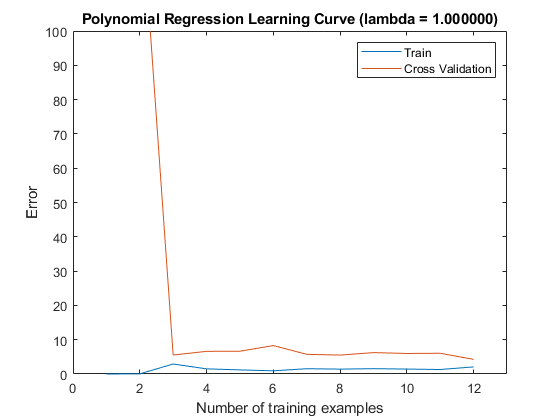

plot(1:m, error_train, 1:m, error_val);
title(sprintf('Polynomial Regression Learning Curve (lambda = %f)', lambda));
xlabel('Number of training examples')
ylabel('Error')
axis([0 13 0 100])
legend('Train', 'Cross Validation')

For each of these values, the code should generate a polynomial fit to the data and also a learning curve.

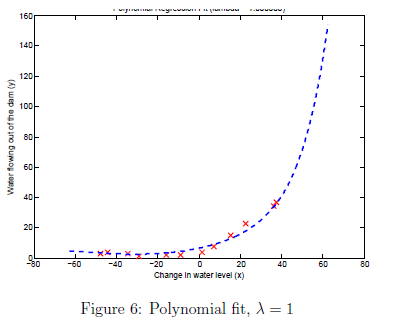

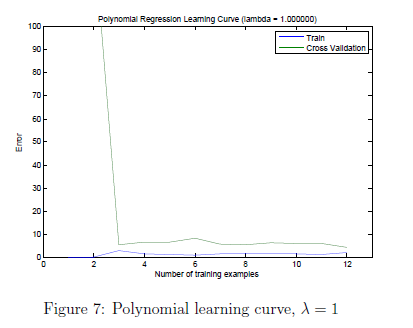

    For $\lambda= 1$, you should see a polynomial fit that follows the data trend well (Figure 6) and a learning curve (Figure 7) showing that both the cross validation and training error converge to a relatively low value. This shows the $\lambda= 1$ regularized polynomial regression model does not have the high bias or high-variance problems. In effect, it achieves a good trade-off between bias and variance.

    For $\lambda= 100$, you should see a polynomial fit (Figure 8) that does not follow the data well. In this case, there is too much regularization and the model is unable to fit the training data.

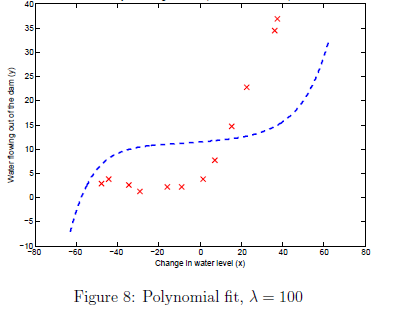

### 3.3 Selecting lambda using a cross validation set

From the previous parts of the exercise, you observed that the value of $\lambda$ can significantly affect the results of regularized polynomial regression on the training and cross validation set. In particular, a model without regularization ($\lambda = 0$) fits the training set well, but does not generalize. Conversely, a model with too much regularization ($\lambda=100$)  does not fit the training set and testing set well. A good choice of $\lambda$ (e.g. $\lambda=1$) can provide a good fit to the data.

    In this section, you will implement an automated method to select the parameter. Concretely, you will use a cross validation set to evaluate how good each $\lambda$ value is. After selecting the best $\lambda$ value using the cross validation set, we can then evaluate the model on the test set to estimate how well the model will perform on actual unseen data. Your task is to complete the code in `validationCurve.m`. Specifically, you should should use the `trainLinearReg` function to train the model using different values of $\lambda$ and compute the training error and cross validation error. The function will try $\lambda$ in the following range: {0, 0.001, 0.003, 0.01, 0.03, 0.1, 0.3, 1, 3, 10}.

    After you have completed the code, the code below will run your function and plot a cross validation curve of error v.s $\lambda$ that allows you select which $\lambda$ parameter to use. You should see a plot similar to Figure 9. 

[lambda_vec, error_train, error_val] = validationCurve(X_poly, y, X_poly_val, yval);

Iteration     1 | Cost: 8.273077e+01
Iteration     2 | Cost: 2.687496e+01
Iteration     3 | Cost: 1.327780e+01
Iteration     4 | Cost: 3.455324e+00
Iteration     5 | Cost: 2.870493e+00
Iteration     6 | Cost: 2.404364e+00
Iteration     7 | Cost: 2.372779e+00
Iteration     8 | Cost: 1.771555e+00
Iteration     9 | Cost: 1.210317e+00
Iteration    10 | Cost: 9.413710e-01
Iteration    11 | Cost: 7.664150e-01
Iteration    12 | Cost: 6.504421e-01
Iteration    13 | Cost: 5.859279e-01
Iteration    14 | Cost: 5.490372e-01
Iteration    15 | Cost: 5.065777e-01
Iteration    16 | Cost: 4.806162e-01
Iteration    17 | Cost: 4.735173e-01
Iteration    18 | Cost: 4.662764e-01
Iteration    19 | Cost: 4.556416e-01
Iteration    20 | Cost: 4.450352e-01
Iteration    21 | Cost: 4.244435e-01
Iteration    22 | Cost: 4.118416e-01
Iteration    23 | Cost: 3.955800e-01
Iteration    24 | Cost: 3.805369e-01
Iteration    25 | Cost: 3.797197e-01
Iteration    26 | Cost: 3.751002e-01
Iteration    27 | Cost: 3.734674e-01
I

theta =    11.2210
   11.3376
   14.2653
   10.9745
  -10.1949
  -13.1182
    5.2428
    1.4204
   -5.0168


Iteration     1 | Cost: 8.273125e+01
Iteration     2 | Cost: 2.687716e+01
Iteration     3 | Cost: 1.328082e+01
Iteration     4 | Cost: 3.462063e+00
Iteration     5 | Cost: 2.876591e+00
Iteration     6 | Cost: 2.410018e+00
Iteration     7 | Cost: 2.378879e+00
Iteration     8 | Cost: 1.778552e+00
Iteration     9 | Cost: 1.211503e+00
Iteration    10 | Cost: 9.413078e-01
Iteration    11 | Cost: 7.813067e-01
Iteration    12 | Cost: 6.678129e-01
Iteration    13 | Cost: 6.351307e-01
Iteration    14 | Cost: 6.022851e-01
Iteration    15 | Cost: 4.922997e-01
Iteration    16 | Cost: 4.450482e-01
Iteration    17 | Cost: 4.281666e-01
Iteration    18 | Cost: 4.263387e-01
Iteration    19 | Cost: 4.253014e-01
Iteration    20 | Cost: 4.241756e-01
Iteration    21 | Cost: 4.180986e-01
Iteration    22 | Cost: 3.965378e-01
Iteration    23 | Cost: 3.945881e-01
Iteration    24 | Cost: 3.922888e-01
Iteration    25 | Cost: 3.663968e-01
Iteration    26 | Cost: 3.507728e-01
Iteration    27 | Cost: 3.488581e-01
I

theta =    11.2176
   11.6593
   13.6177
    9.6658
   -9.3052
  -12.2737
    5.2079
    2.0991
   -4.7316


Iteration     1 | Cost: 8.273221e+01
Iteration     2 | Cost: 2.688156e+01
Iteration     3 | Cost: 1.328685e+01
Iteration     4 | Cost: 3.475543e+00
Iteration     5 | Cost: 2.888786e+00
Iteration     6 | Cost: 2.421323e+00
Iteration     7 | Cost: 2.391085e+00
Iteration     8 | Cost: 1.792698e+00
Iteration     9 | Cost: 1.214309e+00
Iteration    10 | Cost: 9.541155e-01
Iteration    11 | Cost: 8.804539e-01
Iteration    12 | Cost: 6.979211e-01
Iteration    13 | Cost: 6.106966e-01
Iteration    14 | Cost: 5.122910e-01
Iteration    15 | Cost: 5.070537e-01
Iteration    16 | Cost: 4.997648e-01
Iteration    17 | Cost: 4.983492e-01
Iteration    18 | Cost: 4.692366e-01
Iteration    19 | Cost: 4.050899e-01
Iteration    20 | Cost: 4.042206e-01
Iteration    21 | Cost: 3.928682e-01
Iteration    22 | Cost: 3.902556e-01
Iteration    23 | Cost: 3.864752e-01
Iteration    24 | Cost: 3.848531e-01
Iteration    25 | Cost: 3.826372e-01
Iteration    26 | Cost: 3.812144e-01
Iteration    27 | Cost: 3.659702e-01
I

theta =    11.2184
   11.8786
   13.3087
    8.0241
   -6.7406
   -8.0861
    1.1543
   -1.3214
   -3.5519


Iteration     1 | Cost: 8.273556e+01
Iteration     2 | Cost: 2.689698e+01
Iteration     3 | Cost: 1.330795e+01
Iteration     4 | Cost: 3.522725e+00
Iteration     5 | Cost: 2.931455e+00
Iteration     6 | Cost: 2.460864e+00
Iteration     7 | Cost: 2.422567e+00
Iteration     8 | Cost: 1.963501e+00
Iteration     9 | Cost: 1.846304e+00
Iteration    10 | Cost: 1.357147e+00
Iteration    11 | Cost: 9.987401e-01
Iteration    12 | Cost: 7.016182e-01
Iteration    13 | Cost: 6.302110e-01
Iteration    14 | Cost: 5.546654e-01
Iteration    15 | Cost: 5.522792e-01
Iteration    16 | Cost: 5.346351e-01
Iteration    17 | Cost: 5.335461e-01
Iteration    18 | Cost: 5.318629e-01
Iteration    19 | Cost: 5.294109e-01
Iteration    20 | Cost: 5.273738e-01
Iteration    21 | Cost: 5.265774e-01
Iteration    22 | Cost: 5.232757e-01
Iteration    23 | Cost: 5.208805e-01
Iteration    24 | Cost: 5.153398e-01
Iteration    25 | Cost: 5.131768e-01
Iteration    26 | Cost: 5.064025e-01
Iteration    27 | Cost: 5.043720e-01
I

theta =    11.2176
   12.2224
   12.3565
    5.7210
   -4.4552
   -4.7878
   -0.9306
   -2.2514
   -2.4007


Iteration     1 | Cost: 8.274514e+01
Iteration     2 | Cost: 2.694101e+01
Iteration     3 | Cost: 1.336813e+01
Iteration     4 | Cost: 3.657587e+00
Iteration     5 | Cost: 3.053249e+00
Iteration     6 | Cost: 2.573588e+00
Iteration     7 | Cost: 2.538580e+00
Iteration     8 | Cost: 2.118505e+00
Iteration     9 | Cost: 1.650860e+00
Iteration    10 | Cost: 1.450765e+00
Iteration    11 | Cost: 1.335352e+00
Iteration    12 | Cost: 1.042035e+00
Iteration    13 | Cost: 8.571667e-01
Iteration    14 | Cost: 8.232820e-01
Iteration    15 | Cost: 8.043795e-01
Iteration    16 | Cost: 7.891879e-01
Iteration    17 | Cost: 7.869869e-01
Iteration    18 | Cost: 7.790187e-01
Iteration    19 | Cost: 7.748130e-01
Iteration    20 | Cost: 7.687836e-01
Iteration    21 | Cost: 7.671604e-01
Iteration    22 | Cost: 7.635162e-01
Iteration    23 | Cost: 7.503619e-01
Iteration    24 | Cost: 7.264561e-01
Iteration    25 | Cost: 7.180289e-01
Iteration    26 | Cost: 7.134664e-01
Iteration    27 | Cost: 7.112857e-01
I

theta =    11.2176
   12.4496
   11.0215
    3.6176
   -2.2764
   -2.3534
   -1.7573
   -1.9820
   -1.6272


Iteration     1 | Cost: 8.277865e+01
Iteration     2 | Cost: 2.709514e+01
Iteration     3 | Cost: 1.357764e+01
Iteration     4 | Cost: 4.130291e+00
Iteration     5 | Cost: 3.478229e+00
Iteration     6 | Cost: 2.965259e+00
Iteration     7 | Cost: 2.939673e+00
Iteration     8 | Cost: 2.647756e+00
Iteration     9 | Cost: 2.588852e+00
Iteration    10 | Cost: 2.171449e+00
Iteration    11 | Cost: 1.736470e+00
Iteration    12 | Cost: 1.552299e+00
Iteration    13 | Cost: 1.522166e+00
Iteration    14 | Cost: 1.484212e+00
Iteration    15 | Cost: 1.483933e+00
Iteration    16 | Cost: 1.482707e+00
Iteration    17 | Cost: 1.480319e+00
Iteration    18 | Cost: 1.478357e+00
Iteration    19 | Cost: 1.469529e+00
Iteration    20 | Cost: 1.466264e+00
Iteration    21 | Cost: 1.462285e+00
Iteration    22 | Cost: 1.460661e+00
Iteration    23 | Cost: 1.455358e+00
Iteration    24 | Cost: 1.454730e+00
Iteration    25 | Cost: 1.453829e+00
Iteration    26 | Cost: 1.453747e+00
Iteration    27 | Cost: 1.451803e+00
I

theta =    11.2176
   12.0332
    9.0247
    2.4636
   -0.0311
   -0.7517
   -1.1131
   -0.7189
   -1.2504


Iteration     1 | Cost: 8.287440e+01
Iteration     2 | Cost: 2.753557e+01
Iteration     3 | Cost: 1.416686e+01
Iteration     4 | Cost: 5.488365e+00
Iteration     5 | Cost: 4.707237e+00
Iteration     6 | Cost: 4.115951e+00
Iteration     7 | Cost: 4.004377e+00
Iteration     8 | Cost: 3.861957e+00
Iteration     9 | Cost: 3.723422e+00
Iteration    10 | Cost: 3.290208e+00
Iteration    11 | Cost: 3.234342e+00
Iteration    12 | Cost: 3.206575e+00
Iteration    13 | Cost: 3.129420e+00
Iteration    14 | Cost: 3.115200e+00
Iteration    15 | Cost: 3.111567e+00
Iteration    16 | Cost: 3.106992e+00
Iteration    17 | Cost: 3.106941e+00
Iteration    18 | Cost: 3.106506e+00
Iteration    19 | Cost: 3.105955e+00
Iteration    20 | Cost: 3.105530e+00
Iteration    21 | Cost: 3.105269e+00
Iteration    22 | Cost: 3.105044e+00
Iteration    23 | Cost: 3.104315e+00
Iteration    24 | Cost: 3.103347e+00
Iteration    25 | Cost: 3.103344e+00
Iteration    26 | Cost: 3.103271e+00
Iteration    27 | Cost: 3.103053e+00
I

theta =    11.2176
   10.6844
    7.0618
    2.7215
    1.4831
    0.5345
    0.0284
    0.3721
   -0.5757


Iteration     1 | Cost: 8.320954e+01
Iteration     2 | Cost: 2.907694e+01
Iteration     3 | Cost: 1.613078e+01
Iteration     4 | Cost: 8.099229e+00
Iteration     5 | Cost: 7.978585e+00
Iteration     6 | Cost: 7.689198e+00
Iteration     7 | Cost: 7.612530e+00
Iteration     8 | Cost: 7.396000e+00
Iteration     9 | Cost: 7.350173e+00
Iteration    10 | Cost: 7.291198e+00
Iteration    11 | Cost: 7.287920e+00
Iteration    12 | Cost: 7.281753e+00
Iteration    13 | Cost: 7.275793e+00
Iteration    14 | Cost: 7.274328e+00
Iteration    15 | Cost: 7.270014e+00
Iteration    16 | Cost: 7.269538e+00
Iteration    17 | Cost: 7.269020e+00
Iteration    18 | Cost: 7.268392e+00
Iteration    19 | Cost: 7.268362e+00
Iteration    20 | Cost: 7.268325e+00
Iteration    21 | Cost: 7.268219e+00
Iteration    22 | Cost: 7.268170e+00
Iteration    23 | Cost: 7.268168e+00
Iteration    24 | Cost: 7.268158e+00
Iteration    25 | Cost: 7.268157e+00
Iteration    26 | Cost: 7.268153e+00
Iteration    27 | Cost: 7.268151e+00
I

theta =    11.2176
    8.5852
    5.2127
    3.5911
    2.2830
    1.7603
    1.0681
    1.1076
    0.3940


Iteration     1 | Cost: 8.416707e+01
Iteration     2 | Cost: 3.345965e+01
Iteration     3 | Cost: 2.112694e+01
Iteration     4 | Cost: 1.621542e+01
Iteration     5 | Cost: 1.605198e+01
Iteration     6 | Cost: 1.596514e+01
Iteration     7 | Cost: 1.596285e+01
Iteration     8 | Cost: 1.592089e+01
Iteration     9 | Cost: 1.589157e+01
Iteration    10 | Cost: 1.589011e+01
Iteration    11 | Cost: 1.587849e+01
Iteration    12 | Cost: 1.587363e+01
Iteration    13 | Cost: 1.586793e+01
Iteration    14 | Cost: 1.586791e+01
Iteration    15 | Cost: 1.586776e+01
Iteration    16 | Cost: 1.586772e+01
Iteration    17 | Cost: 1.586769e+01
Iteration    18 | Cost: 1.586769e+01
Iteration    19 | Cost: 1.586769e+01
Iteration    20 | Cost: 1.586769e+01
Iteration    21 | Cost: 1.586769e+01
Iteration    22 | Cost: 1.586769e+01
Iteration    23 | Cost: 1.586769e+01
Iteration    24 | Cost: 1.586769e+01
Iteration    25 | Cost: 1.586769e+01
Iteration    26 | Cost: 1.586769e+01
Iteration    27 | Cost: 1.586769e+01
I

theta =    11.2176
    6.6568
    3.8942
    3.7590
    2.2532
    2.2064
    1.3320
    1.3501
    0.7619


Iteration     1 | Cost: 8.751844e+01
Iteration     2 | Cost: 4.781977e+01
Iteration     3 | Cost: 3.633140e+01
Iteration     4 | Cost: 3.345113e+01
Iteration     5 | Cost: 3.340324e+01
Iteration     6 | Cost: 3.337310e+01
Iteration     7 | Cost: 3.337236e+01
Iteration     8 | Cost: 3.337221e+01
Iteration     9 | Cost: 3.337220e+01
Iteration    10 | Cost: 3.337220e+01
Iteration    11 | Cost: 3.337220e+01
Iteration    12 | Cost: 3.337220e+01
Iteration    13 | Cost: 3.337220e+01
Iteration    14 | Cost: 3.337220e+01
Iteration    15 | Cost: 3.337220e+01
Iteration    16 | Cost: 3.337220e+01
Iteration    17 | Cost: 3.337220e+01
Iteration    18 | Cost: 3.337220e+01
Iteration    19 | Cost: 3.337220e+01
Iteration    20 | Cost: 3.337220e+01
Iteration    21 | Cost: 3.337220e+01


theta =    11.2176
    4.3666
    2.3995
    2.9018
    1.5016
    1.8659
    0.8981
    1.1938
    0.5092


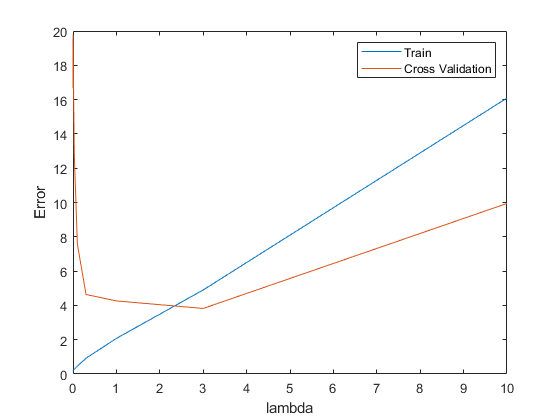

plot(lambda_vec, error_train, lambda_vec, error_val);
legend('Train', 'Cross Validation');
xlabel('lambda');
ylabel('Error');

for i = 1:length(lambda_vec)
    if i == 1
        fprintf('lambda\t\tTrain Error\tValidation Error\n');
    end
    fprintf('%f\t%f\t%f\n',lambda_vec(i), error_train(i), error_val(i));
end

lambda		Train Error	Validation Error


0.000000	0.158145	19.504103
0.001000	0.165346	16.652361
0.003000	0.190536	19.774820
0.010000	0.222923	17.176933
0.030000	0.281851	12.831101
0.100000	0.459318	7.587013
0.300000	0.921760	4.636833
1.000000	2.076188	4.260626
3.000000	4.901351	3.822907
10.000000	16.092213	9.945509


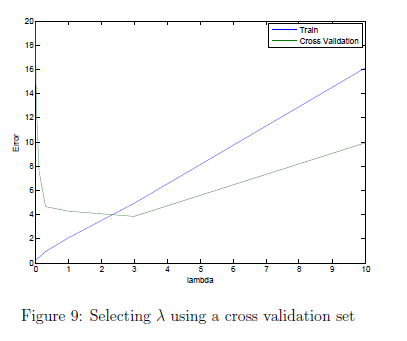

In this figure, we can see that the best value of $\lambda$ is around 3. Due to randomness in the training and validation splits of the dataset, the cross validation error can sometimes be lower than the training error. 

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

### 3.4 Optional (ungraded) exercise: Computing test set error

In the previous part of the exercise, you implemented code to compute the cross validation error for various values of the regularization parameter $\lambda$. However, to get a better indication of the model's performance in the real world, it is important to evaluate the 'final' model on a test set that was not used in any part of training (that is, it was neither used to select the $\lambda$ parameters, nor to learn the model parameters $\theta$).

    For this optional (ungraded) exercise, you should compute the test error using the best value of $\lambda$ you found. In our cross validation, we obtained a test error of 3.8599 for $\lambda= 3.$ You do not need to submit any solutions for this optional (ungraded) exercise.

%%%%%%%%% Add your code to compute the test error below %%%%%%%%%%%



### 3.5 Optional (ungraded) exercise: Plotting learning curves with randomly selected examples

In practice, especially for small training sets, when you plot learning curves to debug your algorithms, it is often helpful to average across multiple sets of randomly selected examples to determine the training error and cross validation error. Concretely, to determine the training error and cross validation error for $i$ examples, you should first randomly select $i$ examples from the training set and $i$ examples from the cross validation set. You will then learn the parameters $\theta$ using the randomly chosen training set and evaluate the parameters $\theta$ on the randomly chosen training set and cross validation set. The above steps should then be repeated multiple times (say 50) and the averaged error should be used to determine the training error and cross validation error for $i$ examples.

     For this optional (ungraded) exercise, you should implement the above strategy for computing the learning curves in `learningCurve.m` and use the code below to call your modified function and generate the plot.

lambda = 0.01;
[error_train, error_val] = learningCurve(X_poly, y, X_poly_val, yval, lambda);

Iteration     1 | Cost: 3.405390e-01
Iteration     2 | Cost: 4.988078e-03
Iteration     3 | Cost: 2.151804e-04
Iteration     4 | Cost: 1.111526e-04
Iteration     5 | Cost: 5.971823e-05
Iteration     6 | Cost: 1.149113e-06
Iteration     7 | Cost: 1.118191e-06
Iteration     8 | Cost: 5.589559e-07
Iteration     9 | Cost: 2.324464e-08
Iteration    10 | Cost: 2.323681e-08
Iteration    11 | Cost: 2.302666e-08
Iteration    12 | Cost: 1.565767e-09
Iteration    13 | Cost: 1.565301e-09
Iteration    14 | Cost: 1.550798e-09
Iteration    15 | Cost: 1.155086e-09
Iteration    16 | Cost: 3.923077e-11
Iteration    17 | Cost: 8.037669e-12
Iteration    18 | Cost: 3.468074e-12
Iteration    19 | Cost: 3.498624e-13
Iteration    20 | Cost: 4.067355e-14
Iteration    21 | Cost: 7.089337e-15
Iteration    22 | Cost: 4.539412e-15
Iteration    23 | Cost: 5.678886e-18
Iteration    24 | Cost: 5.674965e-18
Iteration    25 | Cost: 5.646990e-18
Iteration    26 | Cost: 3.330909e-24
Iteration    27 | Cost: 3.075634e-29
I

theta =     2.1343
   -0.0000
   -0.0000
    0.0000
   -0.0000
    0.0000
   -0.0000
    0.0000
   -0.0000


Iteration     1 | Cost: 5.523568e-02
Iteration     2 | Cost: 3.367312e-03
Iteration     3 | Cost: 3.036906e-03
Iteration     4 | Cost: 3.000389e-03
Iteration     5 | Cost: 2.982069e-03
Iteration     6 | Cost: 2.378578e-03
Iteration     7 | Cost: 2.044465e-03
Iteration     8 | Cost: 2.043431e-03
Iteration     9 | Cost: 1.949135e-03
Iteration    10 | Cost: 1.948250e-03
Iteration    11 | Cost: 1.946975e-03
Iteration    12 | Cost: 1.946167e-03
Iteration    13 | Cost: 1.945917e-03
Iteration    14 | Cost: 1.943627e-03
Iteration    15 | Cost: 1.942199e-03
Iteration    16 | Cost: 1.931710e-03
Iteration    17 | Cost: 1.931225e-03
Iteration    18 | Cost: 1.930558e-03
Iteration    19 | Cost: 1.930548e-03
Iteration    20 | Cost: 1.930473e-03
Iteration    21 | Cost: 1.930448e-03
Iteration    22 | Cost: 1.930113e-03
Iteration    23 | Cost: 1.930111e-03
Iteration    24 | Cost: 1.930108e-03
Iteration    25 | Cost: 1.930106e-03
Iteration    26 | Cost: 1.930106e-03
Iteration    27 | Cost: 1.930103e-03
I

theta =     1.3427
    0.3543
   -0.6076
    0.3455
   -0.3046
    0.1713
   -0.1246
    0.0716
   -0.0479


Iteration     1 | Cost: 3.032734e+01
Iteration     2 | Cost: 1.226927e+00
Iteration     3 | Cost: 7.383164e-01
Iteration     4 | Cost: 2.727993e-01
Iteration     5 | Cost: 2.622976e-01
Iteration     6 | Cost: 2.616915e-01
Iteration     7 | Cost: 2.612460e-01
Iteration     8 | Cost: 2.600987e-01
Iteration     9 | Cost: 2.597820e-01
Iteration    10 | Cost: 2.293193e-01
Iteration    11 | Cost: 2.245222e-01
Iteration    12 | Cost: 2.233166e-01
Iteration    13 | Cost: 2.216354e-01
Iteration    14 | Cost: 2.211828e-01
Iteration    15 | Cost: 2.208628e-01
Iteration    16 | Cost: 2.207706e-01
Iteration    17 | Cost: 2.207157e-01
Iteration    18 | Cost: 2.206993e-01
Iteration    19 | Cost: 2.206900e-01
Iteration    20 | Cost: 2.206839e-01
Iteration    21 | Cost: 2.206780e-01
Iteration    22 | Cost: 2.206654e-01
Iteration    23 | Cost: 2.206531e-01
Iteration    24 | Cost: 2.206316e-01
Iteration    25 | Cost: 2.206176e-01
Iteration    26 | Cost: 2.206126e-01
Iteration    27 | Cost: 2.205933e-01
I

theta =    10.3722
    7.5519
    4.6101
    4.8100
    3.4476
    2.9634
    2.1801
    1.7719
    1.3079


Iteration     1 | Cost: 9.871955e-01
Iteration     2 | Cost: 3.772825e-01
Iteration     3 | Cost: 2.193567e-01
Iteration     4 | Cost: 1.925157e-01
Iteration     5 | Cost: 1.805324e-01
Iteration     6 | Cost: 1.737041e-01
Iteration     7 | Cost: 1.697920e-01
Iteration     8 | Cost: 1.697737e-01
Iteration     9 | Cost: 1.697543e-01
Iteration    10 | Cost: 1.696742e-01
Iteration    11 | Cost: 1.696653e-01
Iteration    12 | Cost: 1.695577e-01
Iteration    13 | Cost: 1.692946e-01
Iteration    14 | Cost: 1.691631e-01
Iteration    15 | Cost: 1.691631e-01
Iteration    16 | Cost: 1.691412e-01
Iteration    17 | Cost: 1.691206e-01
Iteration    18 | Cost: 1.691113e-01
Iteration    19 | Cost: 1.691107e-01
Iteration    20 | Cost: 1.691105e-01
Iteration    21 | Cost: 1.691100e-01
Iteration    22 | Cost: 1.691097e-01
Iteration    23 | Cost: 1.691077e-01
Iteration    24 | Cost: 1.691065e-01
Iteration    25 | Cost: 1.691018e-01
Iteration    26 | Cost: 1.690996e-01
Iteration    27 | Cost: 1.690991e-01
I

theta =    10.4686
    8.2460
    4.9300
    4.5512
    3.1371
    2.3884
    1.6155
    1.1610
    0.7408


Iteration     1 | Cost: 9.146884e+01
Iteration     2 | Cost: 3.038186e+01
Iteration     3 | Cost: 1.030081e+01
Iteration     4 | Cost: 1.913859e+00
Iteration     5 | Cost: 8.754985e-01
Iteration     6 | Cost: 4.891118e-01
Iteration     7 | Cost: 2.774119e-01
Iteration     8 | Cost: 2.390047e-01
Iteration     9 | Cost: 1.993675e-01
Iteration    10 | Cost: 1.958295e-01
Iteration    11 | Cost: 1.936188e-01
Iteration    12 | Cost: 1.673645e-01
Iteration    13 | Cost: 1.659760e-01
Iteration    14 | Cost: 1.658491e-01
Iteration    15 | Cost: 1.619616e-01
Iteration    16 | Cost: 1.599328e-01
Iteration    17 | Cost: 1.598556e-01
Iteration    18 | Cost: 1.588936e-01
Iteration    19 | Cost: 1.586777e-01
Iteration    20 | Cost: 1.580769e-01
Iteration    21 | Cost: 1.578132e-01
Iteration    22 | Cost: 1.574546e-01
Iteration    23 | Cost: 1.554625e-01
Iteration    24 | Cost: 1.546892e-01
Iteration    25 | Cost: 1.536144e-01
Iteration    26 | Cost: 1.531758e-01
Iteration    27 | Cost: 1.529320e-01
I

theta =    10.4023
    8.2249
    4.9577
    4.5664
    3.1198
    2.4192
    1.5786
    1.1965
    0.6983


Iteration     1 | Cost: 6.690068e+01
Iteration     2 | Cost: 1.226122e+01
Iteration     3 | Cost: 1.918807e+00
Iteration     4 | Cost: 7.408589e-01
Iteration     5 | Cost: 3.343811e-01
Iteration     6 | Cost: 1.632769e-01
Iteration     7 | Cost: 1.622905e-01
Iteration     8 | Cost: 1.614093e-01
Iteration     9 | Cost: 1.607877e-01
Iteration    10 | Cost: 1.603903e-01
Iteration    11 | Cost: 1.595782e-01
Iteration    12 | Cost: 1.584839e-01
Iteration    13 | Cost: 1.578608e-01
Iteration    14 | Cost: 1.577202e-01
Iteration    15 | Cost: 1.575145e-01
Iteration    16 | Cost: 1.573827e-01
Iteration    17 | Cost: 1.572555e-01
Iteration    18 | Cost: 1.570690e-01
Iteration    19 | Cost: 1.568587e-01
Iteration    20 | Cost: 1.567651e-01
Iteration    21 | Cost: 1.565152e-01
Iteration    22 | Cost: 1.562889e-01
Iteration    23 | Cost: 1.553569e-01
Iteration    24 | Cost: 1.549644e-01
Iteration    25 | Cost: 1.536730e-01
Iteration    26 | Cost: 1.533377e-01
Iteration    27 | Cost: 1.528568e-01
I

theta =     9.8146
    6.8958
    6.2774
    6.1723
    2.0492
    2.9138
    1.4441
    0.4527
    1.2669


Iteration     1 | Cost: 7.111306e+01
Iteration     2 | Cost: 8.209217e+00
Iteration     3 | Cost: 6.835196e+00
Iteration     4 | Cost: 2.453563e+00
Iteration     5 | Cost: 1.513852e+00
Iteration     6 | Cost: 1.319340e+00
Iteration     7 | Cost: 1.214726e+00
Iteration     8 | Cost: 1.113352e+00
Iteration     9 | Cost: 8.592473e-01
Iteration    10 | Cost: 7.755090e-01
Iteration    11 | Cost: 7.217759e-01
Iteration    12 | Cost: 6.987616e-01
Iteration    13 | Cost: 6.323878e-01
Iteration    14 | Cost: 4.147882e-01
Iteration    15 | Cost: 3.579300e-01
Iteration    16 | Cost: 2.867906e-01
Iteration    17 | Cost: 2.759489e-01
Iteration    18 | Cost: 2.687834e-01
Iteration    19 | Cost: 2.659156e-01
Iteration    20 | Cost: 2.646573e-01
Iteration    21 | Cost: 2.633671e-01
Iteration    22 | Cost: 2.617815e-01
Iteration    23 | Cost: 2.582937e-01
Iteration    24 | Cost: 2.564961e-01
Iteration    25 | Cost: 2.558614e-01
Iteration    26 | Cost: 2.551584e-01
Iteration    27 | Cost: 2.526460e-01
I

theta =    11.1667
   12.3707
    7.5227
    0.1888
   -0.6849
    1.1458
    0.3048
    1.4592
    1.1742


Iteration     1 | Cost: 6.237381e+01
Iteration     2 | Cost: 3.552163e+00
Iteration     3 | Cost: 2.478752e+00
Iteration     4 | Cost: 1.584286e+00
Iteration     5 | Cost: 1.429355e+00
Iteration     6 | Cost: 1.336908e+00
Iteration     7 | Cost: 1.282375e+00
Iteration     8 | Cost: 1.142900e+00
Iteration     9 | Cost: 1.035943e+00
Iteration    10 | Cost: 9.431970e-01
Iteration    11 | Cost: 8.356958e-01
Iteration    12 | Cost: 7.601254e-01
Iteration    13 | Cost: 7.204199e-01
Iteration    14 | Cost: 7.058386e-01
Iteration    15 | Cost: 6.613416e-01
Iteration    16 | Cost: 6.026698e-01
Iteration    17 | Cost: 5.388205e-01
Iteration    18 | Cost: 5.244752e-01
Iteration    19 | Cost: 4.880783e-01
Iteration    20 | Cost: 4.379859e-01
Iteration    21 | Cost: 4.334885e-01
Iteration    22 | Cost: 3.792460e-01
Iteration    23 | Cost: 3.343681e-01
Iteration    24 | Cost: 2.779245e-01
Iteration    25 | Cost: 2.695420e-01
Iteration    26 | Cost: 2.612800e-01
Iteration    27 | Cost: 2.569324e-01
I

theta =    11.3451
   12.5791
    6.9679
   -0.4018
    0.9836
    0.4772
    0.6207
    2.2219
   -0.3965


Iteration     1 | Cost: 5.925570e+01
Iteration     2 | Cost: 4.068142e+00
Iteration     3 | Cost: 3.712843e+00
Iteration     4 | Cost: 1.772035e+00
Iteration     5 | Cost: 1.669434e+00
Iteration     6 | Cost: 1.460934e+00
Iteration     7 | Cost: 1.445103e+00
Iteration     8 | Cost: 1.378711e+00
Iteration     9 | Cost: 1.351654e+00
Iteration    10 | Cost: 1.239756e+00
Iteration    11 | Cost: 1.167952e+00
Iteration    12 | Cost: 1.052884e+00
Iteration    13 | Cost: 9.429418e-01
Iteration    14 | Cost: 9.415266e-01
Iteration    15 | Cost: 9.005184e-01
Iteration    16 | Cost: 7.907939e-01
Iteration    17 | Cost: 7.308461e-01
Iteration    18 | Cost: 7.165163e-01
Iteration    19 | Cost: 6.734994e-01
Iteration    20 | Cost: 6.107782e-01
Iteration    21 | Cost: 6.064758e-01
Iteration    22 | Cost: 5.644982e-01
Iteration    23 | Cost: 5.235749e-01
Iteration    24 | Cost: 5.097905e-01
Iteration    25 | Cost: 5.077370e-01
Iteration    26 | Cost: 4.985106e-01
Iteration    27 | Cost: 4.814319e-01
I

theta =    10.9750
   11.8288
   10.9074
    2.6521
   -4.1665
   -1.0209
   -0.1571
    0.1495
    0.7401


Iteration     1 | Cost: 5.601835e+01
Iteration     2 | Cost: 2.100417e+00
Iteration     3 | Cost: 1.628627e+00
Iteration     4 | Cost: 1.508200e+00
Iteration     5 | Cost: 1.376450e+00
Iteration     6 | Cost: 1.302137e+00
Iteration     7 | Cost: 1.260350e+00
Iteration     8 | Cost: 1.020772e+00
Iteration     9 | Cost: 7.270905e-01
Iteration    10 | Cost: 6.888198e-01
Iteration    11 | Cost: 6.014469e-01
Iteration    12 | Cost: 5.732440e-01
Iteration    13 | Cost: 5.017471e-01
Iteration    14 | Cost: 4.919675e-01
Iteration    15 | Cost: 4.785474e-01
Iteration    16 | Cost: 4.780239e-01
Iteration    17 | Cost: 4.732125e-01
Iteration    18 | Cost: 4.613166e-01
Iteration    19 | Cost: 4.557550e-01
Iteration    20 | Cost: 4.521103e-01
Iteration    21 | Cost: 4.364942e-01
Iteration    22 | Cost: 4.322642e-01
Iteration    23 | Cost: 4.264324e-01
Iteration    24 | Cost: 4.251521e-01
Iteration    25 | Cost: 4.233329e-01
Iteration    26 | Cost: 4.219523e-01
Iteration    27 | Cost: 4.200411e-01
I

theta =    11.0623
   11.9060
   10.2463
    2.9773
   -2.8816
   -2.1940
    0.9448
    0.5470
   -1.2795


Iteration     1 | Cost: 7.187496e+01
Iteration     2 | Cost: 2.281183e+01
Iteration     3 | Cost: 5.007884e+00
Iteration     4 | Cost: 1.413732e+00
Iteration     5 | Cost: 1.311430e+00
Iteration     6 | Cost: 1.246468e+00
Iteration     7 | Cost: 1.216785e+00
Iteration     8 | Cost: 1.098611e+00
Iteration     9 | Cost: 9.722895e-01
Iteration    10 | Cost: 9.574265e-01
Iteration    11 | Cost: 8.960408e-01
Iteration    12 | Cost: 8.668395e-01
Iteration    13 | Cost: 7.565061e-01
Iteration    14 | Cost: 7.079843e-01
Iteration    15 | Cost: 5.598589e-01
Iteration    16 | Cost: 4.591596e-01
Iteration    17 | Cost: 4.590562e-01
Iteration    18 | Cost: 4.460667e-01
Iteration    19 | Cost: 4.275198e-01
Iteration    20 | Cost: 4.233074e-01
Iteration    21 | Cost: 4.141588e-01
Iteration    22 | Cost: 4.134665e-01
Iteration    23 | Cost: 4.127192e-01
Iteration    24 | Cost: 4.123364e-01
Iteration    25 | Cost: 4.107837e-01
Iteration    26 | Cost: 4.094991e-01
Iteration    27 | Cost: 4.081239e-01
I

theta =    11.0275
   11.7369
   10.4337
    3.4409
   -3.0364
   -2.4469
    0.9202
    0.3647
   -1.3768


Iteration     1 | Cost: 8.273556e+01
Iteration     2 | Cost: 2.689698e+01
Iteration     3 | Cost: 1.330795e+01
Iteration     4 | Cost: 3.522725e+00
Iteration     5 | Cost: 2.931455e+00
Iteration     6 | Cost: 2.460864e+00
Iteration     7 | Cost: 2.422567e+00
Iteration     8 | Cost: 1.963501e+00
Iteration     9 | Cost: 1.846304e+00
Iteration    10 | Cost: 1.357147e+00
Iteration    11 | Cost: 9.987401e-01
Iteration    12 | Cost: 7.016182e-01
Iteration    13 | Cost: 6.302110e-01
Iteration    14 | Cost: 5.546654e-01
Iteration    15 | Cost: 5.522792e-01
Iteration    16 | Cost: 5.346351e-01
Iteration    17 | Cost: 5.335461e-01
Iteration    18 | Cost: 5.318629e-01
Iteration    19 | Cost: 5.294109e-01
Iteration    20 | Cost: 5.273738e-01
Iteration    21 | Cost: 5.265774e-01
Iteration    22 | Cost: 5.232757e-01
Iteration    23 | Cost: 5.208805e-01
Iteration    24 | Cost: 5.153398e-01
Iteration    25 | Cost: 5.131768e-01
Iteration    26 | Cost: 5.064025e-01
Iteration    27 | Cost: 5.043720e-01
I

theta =    11.2176
   12.2224
   12.3565
    5.7210
   -4.4552
   -4.7878
   -0.9306
   -2.2514
   -2.4007


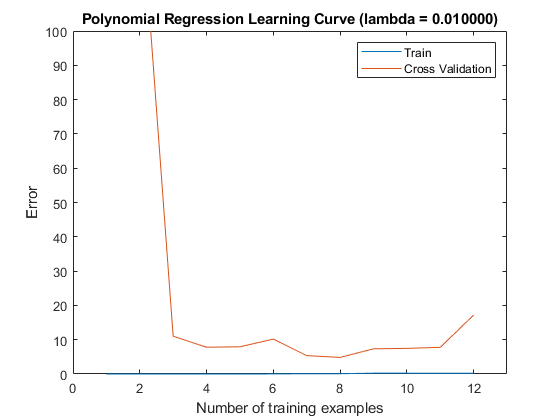

plot(1:m, error_train, 1:m, error_val);

title(sprintf('Polynomial Regression Learning Curve (lambda = %f)', lambda));
xlabel('Number of training examples')
ylabel('Error')
axis([0 13 0 100])
legend('Train', 'Cross Validation')

For reference, Figure 10 shows the learning curve we obtained for polynomial regression with $\lambda= 0.01$. 

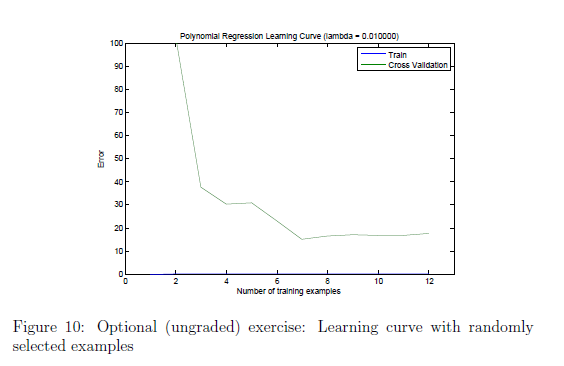

Your figure may differ slightly due to the random selection of examples. 

*You do not need to submit any solutions for this optional (ungraded) exercise.*

## Submission and Grading

After completing various parts of the assignment, be sure to use the submit function system to submit your solutions to our servers. The following is a breakdown of how each part of this exercise is scored.

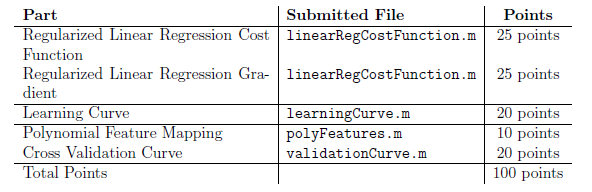

You are allowed to submit your solutions multiple times, and we will take only the highest score into consideration.